
% 用高斯-赛德尔迭代法求二维静电场域的电位分布
hx=25;hy=17;                    % 设置网格节点数
v1=ones(hy,hx);                 % 设置行列二维数组
v1(1:6,1:9)=zeros(6,9);     % 1到6行的1到9列电位为0
m=24;n=16;                      % 横纵向网格数

% 边界的 Dirichlet 边界条件值
v1(1,10:25)=ones(1,16)*100;      % 第1行电位为100V
v1(2:16,25)=ones(15,1)*50;       % 第25列电位为50V
v1(17,1:25)=0;        % 第17行电位为0
v1(2:7,10)=ones(6,1)*50;        % 纵向50V边界    
v1(7,2:10)=ones(1,9)*50;        % 横向50V边界

% 计算加速收敛因子
t1=(cos(pi/m)+cos(pi/n))/2;
w=2/(1+sqrt(1-t1*t1));

% 超松弛迭代法
v2=v1;maxt=1;t=0;                       % 初始化
k=0;
while(maxt>1e-6)                        % 由 v1 迭代，算出 v2，迭代精度为 0.000001
    k=k+1                               % 计算迭代次数
    maxt=0;
    for i=2:7                          % 从 2 到 6 行循环
        for j=11:24                      % 从 11 到 24 列循环
            v2(i,j)=(v1(i,j+1)+v1(i+1,j)+v2(i-1,j)+v2(i,j-1))/4;%拉普拉斯方程差分式
            t=abs(v2(i,j)-v1(i,j));
            if(t>maxt) maxt=t;
                end
        end
    end
    for i=8:16                          % 从 7 到 16 行循环
        for j=2:24                       % 从 2 到 24 列循环
            v2(i,j)=(v1(i,j+1)+v1(i+1,j)+v2(i-1,j)+v2(i,j-1))/4;%拉普拉斯方程差分式
            t=abs(v2(i,j)-v1(i,j));
            if(t>maxt) maxt=t;
                end
        end
    end
    v2(7:16,1)=v2(7:16,2);               % Neumann 条件处理
    v1=v2                                % 迭代一次
end

k = 1

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   38.0000   35.0000   34.2500   34.0625   34.0156   34.0039   34.0010   34.0002   34.0001   34.0000   34.0000   34.0000   34.0000   46.2500   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   22.5000   14.8750   12.7812   12.2109   12.0566   12.0151   12.0040   12.0011   12.0003   12.0001   12.0000   12.0000   12.0000   27.3125   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   18.6250    8.8750    5.9141    5.0312    4.7720    4.6968    4.6752    4.6691    4.6673    4.6669    4.6667    4.6667    4.6667   20.7448  

k = 2

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   51.8750   50.2500   49.2734   48.8750   48.7339   48.6875   48.6729   48.6685   48.6672   48.6668   48.6667   48.6667   51.7292   57.2604   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   33.8438   26.4375   23.4590   22.3555   21.9691   21.8394   21.7971   21.7838   21.7796   21.7783   21.7779   21.7778   26.3715   38.5942   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   27.5938   16.7695   12.2554   10.5203    9.8884    9.6673    9.5922    9.5673    9.5593    9.5567    9.5559    9.5557   14.7236   30.4524  

k = 3

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5234   58.5586   57.7231   57.2031   56.9649   56.8693   56.8337   56.8212   56.8169   56.8155   56.8150   57.5805   60.3031   62.2243   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   40.6387   34.8564   31.7976   30.3725   29.7663   29.5250   29.4337   29.4004   29.3887   29.3847   29.3834   30.7228   36.0859   44.6907   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   33.2358   23.3809   18.3765   16.0746   15.0892   14.6899   14.5350   14.4769   14.4558   14.4484   14.4458   16.0718   23.0912   36.1912  

k = 4

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.2993   63.7197   63.1801   62.6294   62.3163   62.1688   62.1059   62.0808   62.0713   62.0678   62.2579   63.3209   65.4078   65.0246   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   45.0979   40.9990   38.2320   36.6756   35.9015   35.5485   35.3974   35.3360   35.3119   35.3029   35.6823   37.7903   42.7450   48.4902   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   37.2005   28.7331   23.7935   21.1915   19.9271   19.3508   19.1014   18.9979   18.9566   18.9405   19.4369   22.2791   29.4666   40.0134  

k = 5

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   64.7044   67.2209   67.0206   66.5031   66.1433   65.9494   65.8569   65.8160   65.7989   65.8399   66.2108   67.3522   68.7804   66.8177   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   48.2260   45.6030   43.2732   41.7173   40.8341   40.3829   40.1693   40.0738   40.0330   40.1240   40.8905   43.3167   47.5135   51.0861   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   40.1320   33.0294   28.4259   25.7294   24.2787   23.5508   23.2057   23.0497   22.9820   23.1061   24.1777   27.6639   34.3536   42.7606  

k = 6

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   66.3617   69.7463   69.8806   69.4353   69.0547   68.8236   68.7022   68.6437   68.6292   68.7410   69.2459   70.3358   71.1667   68.0632   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   50.5242   49.1433   47.2918   45.8226   44.8848   44.3571   44.0847   43.9528   43.9220   44.1649   45.2263   47.6848   51.0728   52.9742   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   42.3891   36.5145   32.3578   29.7001   28.1452   27.2999   26.8674   26.6570   26.6046   26.9549   28.4948   32.2133   38.1843   44.8395  

k = 7

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   67.5676   71.6479   72.0938   71.7428   71.3628   71.1055   70.9585   70.8851   70.8870   71.0745   71.6591   72.6277   72.9409   68.9788   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   52.2750   51.9323   50.5516   49.2198   48.2712   47.6903   47.3673   47.2078   47.2161   47.6179   48.8642   51.1945   53.8235   54.4104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   44.1804   39.3817   35.7034   33.1651   31.5699   30.6417   30.1348   29.8856   29.8942   30.4868   32.3456   36.0450   41.2573   46.4718  

k = 8

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   68.4807   73.1267   73.8553   73.6095   73.2466   72.9739   72.8066   72.7254   72.7540   73.0078   73.6249   74.4401   74.3106   69.6802   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   53.6484   54.1771   53.2389   52.0712   51.1445   50.5318   50.1703   49.9993   50.0664   50.6063   51.9428   54.0628   56.0103   55.5406   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   45.6357   41.7735   38.5682   36.1954   34.6068   33.6262   33.0635   32.8008   32.9009   33.7089   35.7520   39.2901   43.7738   47.7899  

k = 9

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   69.1938   74.3065   75.2887   75.1516   74.8175   74.5390   74.3586   74.2780   74.3380   74.6423   75.2563   75.9074   75.3995   70.2350   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.7516   56.0176   55.4864   54.4945   53.6126   52.9870   52.6021   52.4368   52.5705   53.2161   54.5718   56.4449   57.7897   56.4536   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   46.8408   43.7946   41.0400   38.8567   37.3079   36.3016   35.7056   35.4553   35.6589   36.6373   38.7606   42.0615   45.8714   48.8780  

k = 10

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   69.7645   75.2677   76.4764   76.4471   76.1497   75.8738   75.6885   75.6158   75.7072   76.0449   76.6310   77.1189   76.2859   70.6849   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.6557   57.5511   57.3905   56.5767   55.7553   55.1332   54.7410   54.5957   54.7945   55.5121   56.8372   58.4518   59.2657   57.2071   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   47.8543   45.5223   43.1892   41.2059   39.7203   38.7116   38.1055   37.8883   38.1937   39.2948   41.4226   44.4503   47.6467   49.7923  

k = 11

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   70.2309   76.0646   77.4756   77.5505   77.2949   77.0292   76.8465   76.7873   76.9067   77.2625   77.8046   78.1356   77.0215   71.0572   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.4091   58.8466   59.0220   58.3834   57.6330   57.0287   56.6441   56.5285   56.7853   57.5449   58.8060   60.1644   60.5099   57.8399   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   48.7183   47.0145   45.0720   43.2910   41.8848   40.8943   40.2994   40.1292   40.5260   41.7067   43.7867   46.5275   49.1687   50.5721  

k = 12

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   70.6184   76.7351   78.3269   78.5013   78.2909   78.0415   77.8682   77.8259   77.9684   78.3295   78.8178   79.0009   77.6420   71.3705   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.0458   59.9544   60.4342   59.9649   59.2923   58.7180   58.3536   58.2735   58.5782   59.3551   60.5310   61.6423   61.5732   58.3790   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   49.4632   48.3152   46.7330   45.1518   43.8367   42.8819   42.3158   42.2004   42.6743   43.8983   45.8954   48.3491   50.4885   51.2455  

k = 13

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   70.9452   77.3066   79.0605   79.3291   79.1657   78.9380   78.7794   78.7553   78.9157   79.2722   79.7010   79.7463   78.1725   71.6379   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.5907   60.9117   61.6675   61.3602   60.7702   60.2359   59.9011   59.8587   60.2010   60.9756   62.0536   62.9306   62.4926   58.8440   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   50.1119   49.4585   48.2081   46.8216   45.6059   44.7012   44.1772   44.1194   44.6552   45.8937   47.7850   49.9587   51.6442   51.8333  

k = 14

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   71.2243   77.7991   79.6989   80.0562   79.9411   79.7391   79.5989   79.5933   79.7666   80.1108   80.4777   80.3952   78.6314   71.8689   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.0620   61.7468   62.7535   62.6004   62.0958   61.6093   61.3110   61.3062   61.6759   62.4335   63.4067   64.0633   63.2957   59.2495   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   50.6818   50.4710   49.5263   48.3280   47.2175   46.3744   45.9019   45.9010   46.4840   47.7146   49.4861   51.3910   52.6648   52.3510  

k = 15

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   71.4653   78.2278   80.2594   80.7002   80.6338   80.4605   80.3412   80.3535   80.5351   80.8616   81.1659   80.9651   79.0324   72.0705   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4735   62.4814   63.7169   63.7102   63.2927   62.8596   62.6022   62.6331   63.0214   63.7511   64.6166   65.0671   64.0035   59.6062   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   51.1863   51.3736   50.7112   49.6941   48.6928   47.9196   47.5046   47.5577   48.1748   49.3806   51.0244   52.6735   53.5730   52.8108  

k = 16

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   71.6753   78.6040   80.7553   81.2748   81.2570   81.1145   81.0176   81.0464   81.2324   81.5373   81.7798   81.4698   79.3859   72.2480   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.8358   63.1326   64.5773   64.7097   64.3798   64.0040   63.7898   63.8538   64.2530   64.9469   65.7045   65.9628   64.6320   59.9227   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   51.6362   52.1834   51.7821   50.9393   50.0493   49.3518   48.9975   49.1005   49.7402   50.9087   52.4213   53.8284   54.3867   53.2220  

k = 17

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   71.8599   78.9369   81.1973   81.7910   81.8213   81.7107   81.6367   81.6807   81.8678   82.1486   82.3307   81.9199   79.7000   72.4057   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   59.1572   63.7137   65.3507   65.6152   65.3725   65.0562   64.8861   64.9801   65.3837   66.0364   66.6878   66.7670   65.1941   60.2054   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   52.0398   52.9141   52.7551   52.0796   51.3019   50.6836   50.3910   50.5393   51.1920   52.3140   53.6949   54.8738   55.1198   53.5920  

k = 18

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.0235   79.2336   81.5938   82.2576   82.3352   82.2570   82.2060   82.2635   82.4489   82.7040   82.8279   82.3237   79.9809   72.5466   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   59.4443   64.2357   66.0500   66.4399   66.2833   66.0275   65.9011   66.0219   66.4248   67.0327   67.5806   67.4931   65.6998   60.4596   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   52.4040   53.5770   53.6437   53.1286   52.4627   51.9255   51.6941   51.8827   52.5405   53.6097   54.8601   55.8245   55.7840   53.9268  

k = 19

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.1695   79.4997   81.9518   82.6817   82.8055   82.7597   82.7311   82.8005   82.9823   83.2107   83.2788   82.6882   80.2336   72.6733   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   59.7023   64.7073   66.6857   67.1948   67.1227   66.9273   66.8436   66.9879   67.3859   67.9467   68.3947   68.1518   66.1573   60.6893   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   52.7346   54.1815   54.4588   54.0976   53.5423   53.0862   52.9146   53.1388   53.7950   54.8072   55.9300   56.6927   56.3886   54.2312  

k = 20

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.3005   79.7399   82.2768   83.0693   83.2379   83.2241   83.2170   83.2968   83.4734   83.6747   83.6894   83.0187   80.4623   72.7879   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   59.9356   65.1357   67.2665   67.8890   67.8991   67.7633   67.7207   67.8856   68.2752   68.7879   69.1398   68.7521   66.5731   60.8980   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   53.0361   54.7353   55.2099   54.9961   54.5493   54.1735   54.0594   54.3147   54.9641   55.9165   56.9153   57.4885   56.9412   54.5092  

k = 21

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.4189   79.9578   82.5734   83.4251   83.6371   83.6543   83.6680   83.7567   83.9267   84.1010   84.0649   83.3198   80.6702   72.8921   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.1476   65.5268   67.7998   68.5300   68.6199   68.5421   68.5388   68.7213   69.1000   69.5643   69.8241   69.3014   66.9527   61.0885   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   53.3123   55.2451   55.9049   55.8322   55.4911   55.1940   55.1346   55.4169   56.0552   56.9463   57.8253   58.2206   57.4482   54.7641  

k = 22

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.5264   80.1567   82.8454   83.7531   84.0068   84.0542   84.0874   84.1839   84.3462   84.4938   84.4095   83.5953   80.8600   72.9871   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.3414   65.8857   68.2915   69.1242   69.2911   69.2695   69.3032   69.5010   69.8667   70.2827   70.4547   69.8058   67.3006   61.2630   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   53.5667   55.7162   56.5503   56.6126   56.3742   56.1534   56.1458   56.4512   57.0750   57.9043   58.6680   58.8961   57.9150   54.9986  

k = 23

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.6245   80.3389   83.0959   84.0567   84.3505   84.4269   84.4785   84.5814   84.7355   84.8569   84.7267   83.8481   81.0340   73.0742   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.5192   66.2165   68.7467   69.6768   69.9177   69.9503   70.0189   70.2295   70.5807   70.9492   71.0374   70.2706   67.6206   61.4234   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   53.8018   56.1534   57.1519   57.3433   57.2040   57.0568   57.0979   57.4230   58.0297   58.7973   59.4503   59.5211   58.3461   55.2151  

k = 24

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.7145   80.5067   83.3275   84.3387   84.6708   84.7749   84.8438   84.9522   85.0975   85.1933   85.0197   84.0811   81.1940   73.1543   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.6832   66.5225   69.1697   70.1923   70.5044   70.5888   70.6900   70.9115   71.2470   71.5688   71.5773   70.7000   67.9159   61.5713   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.0201   56.5605   57.7143   58.0291   57.9852   57.9088   57.9954   58.3370   58.9247   59.6311   60.1781   60.1010   58.7453   55.4155  

k = 25

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.7975   80.6619   83.5426   84.6014   84.9702   85.1007   85.1857   85.2987   85.4347   85.5058   85.2911   84.2963   81.3416   73.2282   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.8350   66.8068   69.5640   70.6747   71.0547   71.1885   71.3203   71.5507   71.8697   72.1460   72.0788   71.0980   68.1891   61.7082   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.2234   56.9410   58.2417   58.6743   58.7222   58.7132   58.8424   59.1977   59.7647   60.4111   60.8567   60.6402   59.1160   55.6015  

k = 26

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.8742   80.8059   83.7428   84.8469   85.2506   85.4062   85.5063   85.6229   85.7496   85.7967   85.5429   84.4956   81.4782   73.2966   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.9761   67.0717   69.9327   71.1272   71.5721   71.7530   71.9131   72.1509   72.4528   72.6848   72.5456   71.4676   68.4425   61.8351   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.4135   57.2976   58.7376   59.2827   59.4184   59.4737   59.6425   60.0091   60.5542   61.1417   61.4905   61.1427   59.4610   55.7745  

k = 27

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.9455   80.9400   83.9299   85.0769   85.5138   85.6933   85.8073   85.9270   86.0441   86.0680   85.7773   84.6808   81.6050   73.3600   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.1077   67.3195   70.2785   71.5526   72.0594   72.2849   72.4714   72.7151   72.9996   73.1887   72.9810   71.8118   68.6782   61.9532   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.5917   57.6329   59.2049   59.8575   60.0771   60.1935   60.3990   60.7747   61.2972   61.8273   62.0836   61.6120   59.7828   55.9358  

k = 28

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.0119   81.0653   84.1052   85.2929   85.7614   85.9634   86.0904   86.2124   86.3200   86.3215   85.9958   84.8531   81.7229   73.4190   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.2308   67.5519   70.6036   71.9534   72.5192   72.7869   72.9978   73.2461   73.5130   73.6607   73.3880   72.1328   68.8979   62.0632   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.7593   57.9488   59.6464   60.4014   60.7012   60.8755   61.1150   61.4978   61.9971   62.4714   62.6395   62.0510   60.0834   56.0865  

k = 29

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.0740   81.1828   84.2698   85.4961   85.9947   86.2180   86.3571   86.4808   86.5788   86.5588   86.2000   85.0139   81.8327   73.4740   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.3463   67.7704   70.9100   72.3317   72.9536   73.2612   73.4949   73.7466   73.9958   74.1035   73.7689   72.4329   69.1031   62.1659   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.9174   58.2473   60.0643   60.9170   61.2933   61.5223   61.7933   62.1814   62.6572   63.0773   63.1612   62.4623   60.3649   56.2275  

k = 30

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.1323   81.2931   84.4248   85.6878   86.2149   86.4583   86.6085   86.7335   86.8220   86.7814   86.3911   85.1642   81.9353   73.5253   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.4550   67.9764   71.1993   72.6894   73.3647   73.7100   73.9646   74.2188   74.4504   74.5195   74.1262   72.7139   69.2950   62.2620   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.0668   58.5299   60.4604   61.4064   61.8555   62.1363   62.4363   62.8284   63.2805   63.6480   63.6517   62.8484   60.6288   56.3598  

k = 31

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.1870   81.3971   84.5710   85.8688   86.4230   86.6854   86.8459   86.9717   87.0509   86.9904   86.5702   85.3049   82.0313   73.5733   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.5576   68.1710   71.4730   73.0282   73.7542   74.1351   74.4090   74.6649   74.8789   74.9109   74.4617   72.9775   69.4749   62.3520   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.2084   58.7980   60.8367   61.8715   62.3900   62.7196   63.0464   63.4410   63.8694   64.1863   64.1134   63.2114   60.8767   56.4839  

k = 32

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.2387   81.4952   84.7092   86.0401   86.6199   86.9002   87.0702   87.1965   87.2664   87.1869   86.7384   85.4368   82.1212   73.6183   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.6545   68.3552   71.7323   73.3495   74.1236   74.5381   74.8299   75.0866   75.2833   75.2795   74.7772   73.2251   69.6438   62.4365   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.3427   59.0527   61.1945   62.3142   62.8985   63.2743   63.6258   64.0217   64.4265   64.6944   64.5485   63.5529   61.1098   56.6007  

k = 33

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.2874   81.5880   84.8401   86.2024   86.8066   87.1037   87.2825   87.4089   87.4698   87.3719   86.8965   85.5607   82.2057   73.6605   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.7463   68.5298   71.9785   73.6547   74.4745   74.9206   75.2289   75.4857   75.6654   75.6272   75.0743   73.4579   69.8025   62.5159   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.4705   59.2951   61.5352   62.7358   63.3828   63.8020   64.1763   64.5726   64.9540   65.1746   64.9590   63.8748   61.3294   56.7106  

k = 34

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.3336   81.6759   84.9642   86.3564   86.9836   87.2967   87.4836   87.6098   87.6618   87.5464   87.0453   85.6772   82.2851   73.7002   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.8335   68.6957   72.2125   73.9448   74.8079   75.2839   75.6074   75.8638   76.0267   75.9555   75.3544   73.6772   69.9519   62.5907   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.5921   59.5260   61.8601   63.1378   63.8444   64.3046   64.6998   65.0955   65.4538   65.6288   65.3467   64.1785   61.5364   56.8142  

k = 35

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.3773   81.7593   85.0820   86.5026   87.1518   87.4798   87.6742   87.8000   87.8433   87.7110   87.1857   85.7870   82.3598   73.7376   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.9163   68.8535   72.4351   74.2209   75.1252   75.6293   75.9668   76.2222   76.3687   76.2657   75.6189   73.8841   70.0927   62.6611   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.7081   59.7464   62.1701   63.5214   64.2846   64.7834   65.1979   65.5923   65.9278   66.0589   65.7134   64.4654   61.7318   56.9121  

k = 36

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.4189   81.8386   85.1941   86.6417   87.3117   87.6538   87.8551   87.9802   88.0150   87.8666   87.3181   85.8905   82.4302   73.7728   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.9951   69.0038   72.6472   74.4839   75.4274   75.9578   76.3083   76.5623   76.6927   76.5593   75.8687   74.0793   70.2256   62.7276   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.8188   59.9569   62.4663   63.8877   64.7047   65.2399   65.6721   66.0645   66.3777   66.4664   66.0604   64.7367   61.9165   57.0045  

k = 37

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.4584   81.9141   85.3007   86.7741   87.4638   87.8192   88.0269   88.1511   88.1776   88.0137   87.4432   85.9882   82.4967   73.8061   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.0703   69.1471   72.8495   74.7347   75.7153   76.2707   76.6330   76.8853   77.0000   76.8372   76.1050   74.2639   70.3512   62.7904   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.9247   60.1581   62.7494   64.2378   65.1059   65.6754   66.1239   66.5137   66.8050   66.8530   66.3891   64.9934   62.0912   57.0920  

k = 38

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.4961   81.9860   85.4024   86.9002   87.6087   87.9766   88.1902   88.3133   88.3317   88.1530   87.5616   86.0805   82.5594   73.8375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.1420   69.2839   73.0426   74.9740   75.9898   76.5687   76.9420   77.1922   77.2915   77.1006   76.3288   74.4385   70.4699   62.8498   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.0260   60.3506   63.0202   64.5726   65.4893   66.0911   66.5546   66.9412   67.2110   67.2199   66.7007   65.2366   62.2567   57.1748  

k = 39

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.5320   82.0546   85.4993   87.0205   87.7467   88.1264   88.3454   88.4673   88.4780   88.2851   87.6736   86.1679   82.6188   73.8672   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.2105   69.4146   73.2270   75.2025   76.2518   76.8528   77.2363   77.4841   77.5684   77.3505   76.5408   74.6038   70.5823   62.9061   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.1229   60.5350   63.2795   64.8929   65.8558   66.4880   66.9653   67.3484   67.5973   67.5684   66.9965   65.4673   62.4135   57.2532  

k = 40

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.5663   82.1200   85.5919   87.1353   87.8784   88.2692   88.4932   88.6138   88.6168   88.4102   87.7797   86.2506   82.6750   73.8953   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.2759   69.5395   73.4033   75.4208   76.5020   77.1238   77.5166   77.7618   77.8316   77.5878   76.7419   74.7605   70.6888   62.9593   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.2158   60.7116   63.5278   65.1995   66.2064   66.8672   67.3572   67.7364   67.9648   67.8996   67.2773   65.6861   62.5623   57.3277  

k = 41

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.5990   82.1826   85.6803   87.2449   88.0040   88.4053   88.6339   88.7531   88.7487   88.5291   87.8804   86.3290   82.7283   73.9219   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.3386   69.6590   73.5720   75.6296   76.7409   77.3825   77.7839   78.0263   78.0819   77.8131   76.9328   74.9092   70.7898   63.0098   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.3049   60.8810   63.7659   65.4932   66.5418   67.2297   67.7313   68.1064   68.3149   68.2148   67.5442   65.8940   62.7035   57.3983  

k = 42

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.6303   82.2424   85.7648   87.3496   88.1240   88.5351   88.7680   88.8858   88.8742   88.6419   87.9759   86.4033   82.7787   73.9471   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.3986   69.7735   73.7334   75.8293   76.9694   77.6295   78.0388   78.2782   78.3201   78.0274   77.1142   75.0503   70.8856   63.0578   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.3904   61.0434   63.9941   65.7746   66.8629   67.5763   68.0887   68.4593   68.6484   68.5147   67.7980   66.0915   62.8377   57.4655  

k = 43

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.6602   82.2996   85.8457   87.4497   88.2386   88.6590   88.8959   89.0121   88.9935   88.7492   88.0667   86.4739   82.8267   73.9711   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.4560   69.8831   73.8880   76.0204   77.1879   77.8655   78.2821   78.5184   78.5469   78.2312   77.2866   75.1844   70.9766   63.1033   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.4725   61.1993   64.2130   66.0443   67.1704   67.9079   68.4301   68.7961   68.9663   68.8003   68.0395   66.2794   62.9652   57.5293  

k = 44

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.6889   82.3544   85.9231   87.5455   88.3481   88.7774   89.0179   89.1324   89.1071   88.8513   88.1529   86.5410   82.8722   73.9939   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.5111   69.9882   74.0362   76.2035   77.3969   78.0911   78.5144   78.7475   78.7630   78.4253   77.4505   75.3119   71.0632   63.1466   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.5513   61.3490   64.4230   66.3030   67.4650   68.2253   68.7566   69.1178   69.2696   69.0725   68.2695   66.4582   63.0866   57.5900  

k = 45

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.7164   82.4069   85.9972   87.6372   88.4529   88.8904   89.1343   89.2472   89.2154   88.9484   88.2350   86.6048   82.9154   74.0155   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.5640   70.0890   74.1782   76.3788   77.5969   78.3068   78.7363   78.9661   78.9691   78.6101   77.6066   75.4332   71.1455   63.1878   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.6269   61.4928   64.6247   66.5510   67.7473   68.5291   69.0687   69.4250   69.5590   69.3321   68.4887   66.6285   63.2022   57.6478  

k = 46

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.7427   82.4572   86.0681   87.7249   88.5531   88.9985   89.2455   89.3567   89.3186   89.0409   88.3131   86.6654   82.9566   74.0361   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.6147   70.1857   74.3143   76.5468   77.7885   78.5131   78.9483   79.1748   79.1656   78.7863   77.7553   75.5487   71.2238   63.2269   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.6997   61.6309   64.8183   66.7891   68.0180   68.8200   69.3673   69.7186   69.8353   69.5797   68.6976   66.7908   63.3122   57.7029  

k = 47

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.7680   82.5055   86.1362   87.8090   88.6490   89.1019   89.3517   89.4613   89.4170   89.1291   88.3875   86.7232   82.9958   74.0557   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.6633   70.2785   74.4449   76.7079   77.9720   78.7106   79.1511   79.3742   79.3532   78.9543   77.8970   75.6587   71.2984   63.2643   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.7696   61.7636   65.0042   67.0175   68.2775   69.0988   69.6531   69.9994   70.0992   69.8160   68.8968   66.9455   63.4172   57.7554  

k = 48

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.7922   82.5517   86.2014   87.8896   88.7409   89.2008   89.4533   89.5611   89.5108   89.2132   88.4583   86.7782   83.0331   74.0743   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.7101   70.3676   74.5703   76.8623   78.1478   78.8996   79.3451   79.5647   79.5323   79.1146   78.0321   75.7636   71.3695   63.2998   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.8368   61.8911   65.1829   67.2368   68.5265   69.3659   69.9268   70.2679   70.3515   70.0417   69.0870   67.0931   63.5173   57.8055  

k = 49

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.8154   82.5961   86.2640   87.9668   88.8289   89.2954   89.5504   89.6565   89.6005   89.2934   88.5259   86.8306   83.0686   74.0921   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.7550   70.4531   74.6906   77.0105   78.3164   79.0807   79.5306   79.7468   79.7033   79.2676   78.1610   75.8636   71.4373   63.3337   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.9015   62.0138   65.3545   67.4474   68.7653   69.6219   70.1888   70.5248   70.5926   70.2573   69.2686   67.2339   63.6128   57.8533  

k = 50

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.8378   82.6387   86.3240   88.0408   88.9132   89.3861   89.6433   89.7476   89.6861   89.3699   88.5904   86.8806   83.1025   74.1091   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.7981   70.5353   74.8061   77.1527   78.4780   79.2541   79.7083   79.9210   79.8668   79.4138   78.2841   75.9590   71.5020   63.3661   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.9637   62.1317   65.5195   67.6497   68.9945   69.8675   70.4398   70.7707   70.8233   70.4633   69.4421   67.3684   63.7039   57.8989  

k = 51

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.8592   82.6796   86.3816   88.1119   88.9940   89.4729   89.7322   89.8348   89.7679   89.4430   88.6519   86.9284   83.1349   74.1252   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.8395   70.6142   74.9170   77.2891   78.6329   79.4204   79.8784   80.0877   80.0232   79.5534   78.4016   76.0501   71.5637   63.3970   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.0235   62.2451   65.6781   67.8440   69.2145   70.1029   70.6804   71.0062   71.0439   70.6603   69.6078   67.4969   63.7910   57.

k = 52

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.8798   82.7189   86.4370   88.1800   89.0715   89.5560   89.8173   89.9182   89.8461   89.5129   88.7107   86.9739   83.1657   74.1407   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.8794   70.6901   75.0236   77.4201   78.7816   79.5797   80.0413   80.2472   80.1727   79.6869   78.5139   76.1371   71.6227   63.4264   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.0811   62.3543   65.8306   68.0307   69.4258   70.3288   70.9110   71.2318   71.2552   70.8488   69.7663   67.6198   63.8742   57.

k = 53

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.8996   82.7567   86.4901   88.2454   89.1458   89.6357   89.8988   89.9980   89.9209   89.5796   88.7668   87.0174   83.1952   74.1554   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.9177   70.7631   75.1260   77.5459   78.9243   79.7325   80.1974   80.4000   80.3157   79.8145   78.6212   76.2203   71.6790   63.4546   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.1365   62.4592   65.9773   68.2101   69.6287   70.5456   71.1321   71.4478   71.4574   71.0291   69.9179   67.7372   63.9538   58.

k = 54

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.9186   82.7929   86.5411   88.3082   89.2170   89.7121   89.9769   90.0744   89.9924   89.6434   88.8205   87.0590   83.2234   74.1695   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.9545   70.8332   75.2244   77.6667   79.0612   79.8791   80.3470   80.5462   80.4526   79.9366   78.7238   76.2998   71.7329   63.4816   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.1899   62.5603   66.1183   68.3826   69.8235   70.7536   71.3442   71.6549   71.6511   71.2018   70.0629   67.8495   64.0299   58.

k = 55

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.9369   82.8278   86.5901   88.3685   89.2855   89.7854   90.0517   90.1476   90.0609   89.7045   88.8718   87.0987   83.2503   74.1830   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.9900   70.9006   75.3189   77.7828   79.1927   80.0197   80.4904   80.6864   80.5838   80.0535   78.8220   76.3758   71.7844   63.5073   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.2412   62.6575   66.2540   68.5484   70.0107   70.9534   71.5476   71.8535   71.8366   71.3671   70.2018   67.9570   64.1027   58.

k = 56

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.9544   82.8613   86.6372   88.4264   89.3511   89.8556   90.1234   90.2177   90.1265   89.7629   88.9209   87.1367   83.2760   74.1958   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.0241   70.9654   75.4099   77.8943   79.3190   80.1546   80.6280   80.8207   80.7093   80.1653   78.9160   76.4485   71.8336   63.5319   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.2907   62.7511   66.3845   68.7078   70.1906   71.1452   71.7428   72.0439   72.0145   71.5254   70.3347   68.0599   64.1723   58.

k = 57

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.9713   82.8935   86.6824   88.4820   89.4141   89.9230   90.1922   90.2848   90.1893   89.8189   88.9679   87.1731   83.3006   74.2081   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.0569   71.0278   75.4973   78.0015   79.4402   80.2841   80.7599   80.9495   80.8296   80.2725   79.0059   76.5181   71.8808   63.5555   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.3383   62.8411   66.5101   68.8611   70.3634   71.3293   71.9301   72.2265   72.1850   71.6772   70.4620   68.1584   64.2391   58.

k = 58

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.9876   82.9245   86.7259   88.5354   89.4747   89.9877   90.2581   90.3492   90.2494   89.8725   89.0129   87.2079   83.3242   74.2199   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.0884   71.0878   75.5813   78.1045   79.5567   80.4084   80.8865   81.0730   80.9450   80.3751   79.0920   76.5848   71.9259   63.5781   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.3841   62.9279   66.6309   69.0085   70.5296   71.5063   72.1100   72.4017   72.3484   71.8226   70.5840   68.2528   64.3029   58.

k = 59

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0032   82.9542   86.7677   88.5867   89.5328   90.0498   90.3214   90.4110   90.3071   89.9238   89.0559   87.2412   83.3468   74.2312   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.1188   71.1456   75.6622   78.2035   79.6686   80.5278   81.0080   81.1914   81.0555   80.4735   79.1746   76.6486   71.9691   63.5997   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.4282   63.0113   66.7472   69.1503   70.6893   71.6762   72.2827   72.5698   72.5052   71.9620   70.7010   68.3432   64.3642   58.

k = 60

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0183   82.9829   86.8079   88.6361   89.5886   90.1095   90.3821   90.4702   90.3624   89.9729   89.0972   87.2731   83.3684   74.2420   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.1480   71.2011   75.7400   78.2987   79.7761   80.6425   81.1247   81.3050   81.1615   80.5678   79.2536   76.7098   72.0105   63.6204   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.4708   63.0917   66.8592   69.2867   70.8429   71.8396   72.4485   72.7312   72.6557   72.0957   70.8131   68.4299   64.4228   58.

k = 61

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0327   83.0104   86.8466   88.6835   89.6423   90.1667   90.4404   90.5269   90.4154   90.0201   89.1367   87.3037   83.3891   74.2524   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.1762   71.2546   75.8148   78.3903   79.8795   80.7526   81.2366   81.4141   81.2632   80.6582   79.3294   76.7684   72.0502   63.6402   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.5117   63.1691   66.9669   69.4180   70.9906   71.9966   72.6078   72.8861   72.8000   72.2240   70.9206   68.5130   64.4791   58.

k = 62

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0466   83.0370   86.8838   88.7291   89.6938   90.2217   90.4963   90.5814   90.4662   90.0653   89.1746   87.3330   83.4089   74.2623   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.2032   71.3060   75.8868   78.4783   79.9788   80.8584   81.3442   81.5187   81.3608   80.7449   79.4021   76.8246   72.0882   63.6593   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.5512   63.2437   67.0706   69.5443   71.1326   72.1474   72.7608   73.0349   72.9386   72.3470   71.0237   68.5927   64.5330   58.

k = 63

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0600   83.0625   86.9196   88.7729   89.7434   90.2745   90.5500   90.6337   90.5149   90.1086   89.2109   87.3611   83.4279   74.2718   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.2293   71.3556   75.9560   78.5630   80.0743   80.9601   81.4474   81.6192   81.4544   80.8280   79.4718   76.8784   72.1247   63.6775   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.5892   63.3155   67.1705   69.6658   71.2692   72.2925   72.9079   73.1778   73.0716   72.4651   71.1226   68.6692   64.5847   58.

k = 64

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0729   83.0870   86.9540   88.8151   89.7910   90.3253   90.6016   90.6839   90.5617   90.1502   89.2458   87.3880   83.4461   74.2809   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.2544   71.4032   76.0227   78.6445   80.1662   81.0579   81.5466   81.7157   81.5443   80.9078   79.5387   76.9301   72.1596   63.6950   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.6258   63.3846   67.2666   69.7828   71.4006   72.4320   73.0492   73.3150   73.1993   72.5785   71.2175   68.7425   64.6343   58.

k = 65

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0854   83.1106   86.9871   88.8556   89.8368   90.3741   90.6512   90.7321   90.6066   90.1901   89.2792   87.4139   83.4636   74.2896   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.2786   71.4491   76.0868   78.7229   80.2545   81.1518   81.6420   81.8083   81.6305   80.9844   79.6028   76.9797   72.1932   63.7118   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.6610   63.4512   67.3592   69.8953   71.5270   72.5661   73.1851   73.4469   73.3220   72.6873   71.3086   68.8129   64.6820   58.

k = 66

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0973   83.1334   87.0190   88.8947   89.8808   90.4209   90.6988   90.7784   90.6498   90.2283   89.3113   87.4386   83.4804   74.2980   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.3019   71.4933   76.1486   78.7983   80.3395   81.2421   81.7336   81.8974   81.7134   81.0580   79.6644   77.0273   72.2253   63.7279   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.6950   63.5154   67.4483   70.0037   71.6486   72.6951   73.3156   73.5736   73.4399   72.7918   71.3961   68.8805   64.7277   58.

k = 67

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1088   83.1553   87.0496   88.9322   89.9231   90.4660   90.7445   90.8229   90.6912   90.2651   89.3420   87.4624   83.4964   74.3061   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.3243   71.5359   76.2080   78.8708   80.4212   81.3290   81.8216   81.9829   81.7930   81.1286   79.7235   77.0729   72.2562   63.7433   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.7278   63.5771   67.5341   70.1080   71.7657   72.8192   73.4412   73.6954   73.5531   72.8922   71.4801   68.9454   64.7716   58.

k = 68

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1199   83.1763   87.0791   88.9683   89.9639   90.5093   90.7885   90.8656   90.7309   90.3004   89.3716   87.4852   83.5119   74.3138   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.3459   71.5768   76.2652   78.9407   80.4998   81.4125   81.9063   82.0651   81.8694   81.1964   79.7803   77.1168   72.2859   63.7581   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.7593   63.6367   67.6168   70.2084   71.8783   72.9385   73.5619   73.8125   73.6619   72.9887   71.5608   69.0077   64.8137   58.

k = 69

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1306   83.1966   87.1075   89.0030   90.0030   90.5510   90.8307   90.9067   90.7691   90.3343   89.3999   87.5071   83.5267   74.3212   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.3667   71.6163   76.3203   79.0079   80.5754   81.4928   81.9876   82.1440   81.9428   81.2615   79.8348   77.1589   72.3144   63.7724   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.7897   63.6940   67.6964   70.3051   71.9867   73.0533   73.6780   73.9250   73.7664   73.0813   71.6383   69.0675   64.8542   58.

k = 70

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1408   83.2162   87.1349   89.0365   90.0407   90.5911   90.8713   90.9461   90.8058   90.3668   89.4272   87.5282   83.5409   74.3283   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.3867   71.6543   76.3734   79.0726   80.6482   81.5701   82.0659   82.2200   82.0134   81.3241   79.8871   77.1993   72.3417   63.7861   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.8190   63.7493   67.7731   70.3982   72.0911   73.1638   73.7897   74.0332   73.8669   73.1704   71.7128   69.1250   64.8930   58.

k = 71

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1507   83.2350   87.1612   89.0686   90.0770   90.6296   90.9104   90.9840   90.8411   90.3981   89.4533   87.5484   83.5546   74.3352   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4060   71.6909   76.4245   79.1349   80.7182   81.6444   82.1411   82.2930   82.0813   81.3842   79.9374   77.2381   72.3680   63.7992   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.8472   63.8025   67.8470   70.4879   72.1915   73.2701   73.8971   74.1373   73.9635   73.2560   71.7844   69.1802   64.9304   58.

k = 72

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1602   83.2531   87.1865   89.0996   90.1119   90.6667   90.9480   91.0205   90.8750   90.4281   89.4785   87.5678   83.5677   74.3417   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4246   71.7262   76.4736   79.1948   80.7856   81.7159   82.2135   82.3631   82.1465   81.4420   79.9857   77.2754   72.3932   63.8118   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.8744   63.8538   67.9181   70.5742   72.2882   73.3724   74.0005   74.2374   74.0564   73.3382   71.8531   69.2333   64.9663   58.

k = 73

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1694   83.2705   87.2109   89.1294   90.1454   90.7023   90.9841   91.0555   90.9075   90.4570   89.5026   87.5865   83.5803   74.3480   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4425   71.7601   76.5210   79.2526   80.8505   81.7847   82.2831   82.4306   82.2091   81.4975   80.0322   77.3113   72.4174   63.8239   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.9006   63.9032   67.9867   70.6574   72.3813   73.4709   74.0999   74.3337   74.1458   73.4173   71.9193   69.2843   65.0008   58.

k = 74

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1783   83.2873   87.2344   89.1581   90.1777   90.7366   91.0188   91.0892   90.9388   90.4848   89.5258   87.6044   83.5925   74.3541   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4598   71.7928   76.5666   79.3082   80.9130   81.8509   82.3501   82.4955   82.2694   81.5509   80.0768   77.3457   72.4407   63.8356   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.9259   63.9509   68.0527   70.7374   72.4709   73.5657   74.1956   74.4263   74.2317   73.4934   71.9828   69.3334   65.0339   58.

k = 75

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1868   83.3035   87.2571   89.1857   90.2088   90.7696   91.0522   91.1217   90.9690   90.5114   89.5482   87.6216   83.6041   74.3599   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4764   71.8243   76.6106   79.3617   80.9731   81.9146   82.4145   82.5580   82.3274   81.6023   80.1197   77.3789   72.4631   63.8468   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.9502   63.9968   68.1164   70.8146   72.5573   73.6569   74.2877   74.5154   74.3143   73.5665   72.0439   69.3805   65.0658   58.

k = 76

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1950   83.3191   87.2789   89.2123   90.2388   90.8014   91.0844   91.1528   90.9979   90.5371   89.5696   87.6381   83.6153   74.3655   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4924   71.8547   76.6529   79.4132   81.0310   81.9760   82.4765   82.6180   82.3831   81.6516   80.1610   77.4107   72.4846   63.8576   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.9737   64.0410   68.1777   70.8889   72.6404   73.7448   74.3763   74.6011   74.3938   73.6369   72.1027   69.4259   65.0965   58.

k = 77

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2029   83.3341   87.2998   89.2380   90.2676   90.8320   91.1153   91.1828   91.0258   90.5617   89.5902   87.6541   83.6261   74.3709   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5078   71.8840   76.6937   79.4629   81.0867   82.0350   82.5362   82.6758   82.4368   81.6991   80.2007   77.4413   72.5053   63.8679   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.9963   64.0836   68.2367   70.9604   72.7204   73.8293   74.4616   74.6836   74.4703   73.7045   72.1592   69.4695   65.1259   58.

k = 78

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2105   83.3486   87.3200   89.2626   90.2953   90.8614   91.1451   91.2117   91.0525   90.5855   89.6101   87.6694   83.6364   74.3761   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5227   71.9121   76.7329   79.5107   81.1403   82.0918   82.5936   82.7314   82.4883   81.7448   80.2388   77.4708   72.5252   63.8779   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.0181   64.1247   68.2936   71.0294   72.7975   73.9108   74.5437   74.7630   74.5439   73.7696   72.2136   69.5114   65.1543   58.

k = 79

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2178   83.3625   87.3395   89.2864   90.3220   90.8897   91.1737   91.2394   91.0783   90.6083   89.6291   87.6841   83.6463   74.3811   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5370   71.9393   76.7708   79.5567   81.1920   82.1465   82.6488   82.7849   82.5380   81.7887   80.2755   77.4991   72.5444   63.8874   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.0391   64.1643   68.3485   71.0958   72.8717   73.9892   74.6228   74.8394   74.6147   73.8323   72.2659   69.5517   65.1815   58.

k = 80

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2249   83.3759   87.3583   89.3093   90.3478   90.9170   91.2013   91.2661   91.1031   90.6302   89.6475   87.6982   83.6559   74.3858   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5508   71.9654   76.8072   79.6011   81.2418   82.1992   82.7020   82.8364   82.5857   81.8309   80.3108   77.5263   72.5628   63.8966   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.0594   64.2024   68.4013   71.1597   72.9433   74.0647   74.6989   74.9130   74.6829   73.8925   72.3162   69.5905   65.2078   58.

k = 81

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2317   83.3888   87.3763   89.3313   90.3725   90.9433   91.2279   91.2918   91.1269   90.6513   89.6651   87.7118   83.6651   74.3904   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5641   71.9907   76.8423   79.6438   81.2897   82.2499   82.7533   82.8859   82.6317   81.8716   80.3448   77.5525   72.5805   63.9055   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.0789   64.2392   68.4522   71.2214   73.0121   74.1374   74.7721   74.9838   74.7484   73.9505   72.3646   69.6279   65.2330   58.

k = 82

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2382   83.4013   87.3937   89.3525   90.3964   90.9685   91.2534   91.3166   91.1499   90.6716   89.6821   87.7249   83.6740   74.3949   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5769   72.0149   76.8762   79.6849   81.3358   82.2987   82.8026   82.9336   82.6759   81.9107   80.3775   77.5777   72.5975   63.9140   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.0977   64.2746   68.5013   71.2808   73.0785   74.2074   74.8427   75.0519   74.8116   74.0063   72.4112   69.6638   65.2573   58.

k = 83

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2446   83.4133   87.4105   89.3729   90.4193   90.9929   91.2780   91.3404   91.1720   90.6912   89.6984   87.7375   83.6825   74.3991   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5893   72.0384   76.9088   79.7246   81.3803   82.3458   82.8500   82.9796   82.7185   81.9484   80.4089   77.6019   72.6139   63.9222   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1159   64.3088   68.5486   71.3380   73.1424   74.2748   74.9106   75.1175   74.8723   74.0600   72.4561   69.6984   65.2806   58.

k = 84

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2507   83.4249   87.4266   89.3926   90.4414   91.0163   91.3017   91.3633   91.1932   90.7100   89.7141   87.7496   83.6907   74.4032   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6012   72.0609   76.9402   79.7628   81.4231   82.3911   82.8957   83.0238   82.7594   81.9846   80.4392   77.6253   72.6297   63.9301   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1333   64.3417   68.5941   71.3931   73.2040   74.3398   74.9760   75.1807   74.9308   74.1117   72.4992   69.7316   65.3031   58.

k = 85

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2565   83.4360   87.4422   89.4116   90.4628   91.0389   91.3245   91.3854   91.2137   90.7281   89.7292   87.7613   83.6986   74.4072   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6127   72.0826   76.9704   79.7996   81.4643   82.4347   82.9397   83.0663   82.7989   82.0195   80.4683   77.6477   72.6449   63.9377   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1502   64.3734   68.6381   71.4463   73.2633   74.4023   75.0391   75.2416   74.9872   74.1615   72.5408   69.7637   65.3248   58.

k = 86

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2622   83.4468   87.4572   89.4299   90.4833   91.0606   91.3464   91.4066   91.2334   90.7455   89.7438   87.7725   83.7061   74.4110   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6238   72.1036   76.9996   79.8350   81.5041   82.4767   82.9821   83.1073   82.8368   82.0530   80.4963   77.6693   72.6595   63.9450   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1664   64.4040   68.6804   71.4975   73.3205   74.4626   75.0997   75.3001   75.0414   74.2094   72.5807   69.7945   65.3456   58.

k = 87

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2676   83.4571   87.4717   89.4475   90.5030   91.0815   91.3676   91.4271   91.2524   90.7623   89.7578   87.7833   83.7134   74.4146   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6344   72.1238   77.0277   79.8692   81.5424   82.5172   83.0229   83.1467   82.8734   82.0854   80.5233   77.6901   72.6735   63.9520   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1821   64.4335   68.7212   71.5468   73.3755   74.5207   75.1582   75.3566   75.0936   74.2555   72.6192   69.8241   65.3656   58.

k = 88

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2729   83.4671   87.4856   89.4645   90.5221   91.1017   91.3879   91.4468   91.2706   90.7784   89.7713   87.7937   83.7205   74.4181   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6447   72.1432   77.0548   79.9021   81.5792   82.5561   83.0622   83.1847   82.9086   82.1165   80.5493   77.7102   72.6871   63.9588   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1972   64.4619   68.7605   71.5944   73.4286   74.5766   75.2145   75.4109   75.1439   74.3000   72.6563   69.8527   65.3849   58.

k = 89

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2779   83.4767   87.4990   89.4808   90.5404   91.1211   91.4075   91.4657   91.2882   90.7940   89.7842   87.8037   83.7272   74.4215   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6546   72.1620   77.0809   79.9338   81.6147   82.5937   83.1001   83.2213   82.9425   82.1464   80.5743   77.7294   72.7001   63.9653   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2118   64.4893   68.7984   71.6402   73.4797   74.6305   75.2687   75.4632   75.1923   74.3427   72.6920   69.8802   65.4035   58.

k = 90

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2828   83.4860   87.5119   89.4965   90.5581   91.1398   91.4264   91.4840   91.3051   90.8089   89.7967   87.8134   83.7337   74.4248   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6641   72.1801   77.1061   79.9644   81.6490   82.6299   83.1366   83.2566   82.9751   82.1753   80.5984   77.7480   72.7126   63.9716   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2258   64.5157   68.8349   71.6843   73.5290   74.6824   75.3209   75.5136   75.2389   74.3839   72.7263   69.9067   65.4214   58.

k = 91

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2875   83.4949   87.5244   89.5117   90.5751   91.1578   91.4446   91.5016   91.3214   90.8233   89.8088   87.8226   83.7400   74.4279   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6734   72.1975   77.1303   79.9938   81.6820   82.6647   83.1717   83.2905   83.0065   82.2030   80.6215   77.7659   72.7247   63.9776   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2393   64.5412   68.8702   71.7269   73.5765   74.7324   75.3713   75.5622   75.2839   74.4236   72.7594   69.9322   65.4386   58.

k = 92

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2921   83.5035   87.5364   89.5263   90.5915   91.1752   91.4621   91.5185   91.3371   90.8372   89.8203   87.8316   83.7460   74.4309   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6822   72.2143   77.1537   80.0222   81.7137   82.6983   83.2055   83.3232   83.0368   82.2298   80.6439   77.7831   72.7363   63.9834   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2524   64.5657   68.9041   71.7679   73.6222   74.7806   75.4198   75.6089   75.3271   74.4618   72.7913   69.9567   65.4552   58.

k = 93

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2964   83.5118   87.5479   89.5404   90.6073   91.1919   91.4790   91.5348   91.3522   90.8506   89.8315   87.8402   83.7519   74.4338   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6908   72.2305   77.1762   80.0496   81.7444   82.7306   83.2381   83.3547   83.0659   82.2555   80.6653   77.7996   72.7475   63.9890   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2649   64.5894   68.9368   71.8075   73.6663   74.8271   75.4665   75.6540   75.3688   74.4986   72.8220   69.9804   65.4712   58.

k = 94

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3006   83.5198   87.5591   89.5540   90.6226   91.2080   91.4953   91.5505   91.3668   90.8634   89.8422   87.8484   83.7574   74.4366   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6990   72.2461   77.1979   80.0759   81.7739   82.7618   83.2695   83.3850   83.0940   82.2803   80.6860   77.8156   72.7583   63.9944   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2771   64.6122   68.9683   71.8456   73.7088   74.8718   75.5115   75.6974   75.4089   74.5340   72.8515   70.0031   65.4865   58.

k = 95

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3047   83.5275   87.5698   89.5671   90.6372   91.2236   91.5109   91.5657   91.3808   90.8758   89.8526   87.8564   83.7628   74.4393   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7070   72.2611   77.2188   80.1013   81.8023   82.7918   83.2998   83.4142   83.1211   82.3042   80.7060   77.8310   72.7687   63.9996   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2888   64.6342   68.9987   71.8823   73.7498   74.9150   75.5548   75.7392   75.4476   74.5681   72.8800   70.0251   65.5014   58.

k = 96

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3086   83.5349   87.5802   89.5797   90.6514   91.2385   91.5260   91.5803   91.3943   90.8878   89.8625   87.8641   83.7680   74.4419   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7146   72.2756   77.2390   80.1258   81.8297   82.8207   83.3289   83.4424   83.1471   82.3272   80.7252   77.8457   72.7787   64.0046   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3000   64.6554   69.0280   71.9177   73.7892   74.9565   75.5966   75.7795   75.4848   74.6010   72.9074   70.0462   65.5156   58.

k = 97

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3124   83.5421   87.5902   89.5918   90.6650   91.2529   91.5405   91.5943   91.4073   90.8993   89.8721   87.8715   83.7730   74.4444   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7220   72.2896   77.2584   80.1494   81.8561   82.8486   83.3570   83.4695   83.1722   82.3494   80.7437   77.8600   72.7883   64.0094   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3109   64.6758   69.0563   71.9518   73.8273   74.9966   75.6369   75.8183   75.5207   74.6327   72.9338   70.0665   65.5294   58.

k = 98

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3160   83.5490   87.5998   89.6036   90.6781   91.2668   91.5545   91.6078   91.4198   90.9103   89.8814   87.8786   83.7778   74.4468   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7291   72.3031   77.2771   80.1722   81.8815   82.8755   83.3841   83.4956   83.1964   82.3708   80.7615   77.8737   72.7976   64.0141   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3214   64.6955   69.0835   71.9847   73.8639   75.0352   75.6757   75.8557   75.5553   74.6632   72.9592   70.0861   65.5426   58.

k = 99

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3195   83.5556   87.6091   89.6148   90.6908   91.2802   91.5680   91.6209   91.4319   90.9210   89.8903   87.8855   83.7825   74.4491   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7360   72.3161   77.2952   80.1941   81.9061   82.9014   83.4102   83.5208   83.2197   82.3913   80.7786   77.8870   72.8065   64.0185   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3315   64.7145   69.1098   72.0164   73.8993   75.0723   75.7130   75.8917   75.5886   74.6926   72.9837   70.1050   65.5554   58.

k = 100

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3229   83.5620   87.6180   89.6257   90.7030   91.2931   91.5810   91.6334   91.4435   90.9313   89.8988   87.8921   83.7869   74.4514   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7426   72.3286   77.3126   80.2152   81.9297   82.9263   83.4353   83.5450   83.2421   82.4112   80.7952   77.8997   72.8151   64.0228   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3412   64.7329   69.1351   72.0470   73.9333   75.1082   75.7491   75.9264   75.6207   74.7209   73.0074   70.1232   65.5676   58.

k = 101

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3262   83.5682   87.6266   89.6362   90.7148   91.3055   91.5936   91.6455   91.4547   90.9412   89.9071   87.8984   83.7912   74.4535   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7490   72.3407   77.3294   80.2356   81.9525   82.9504   83.4595   83.5684   83.2637   82.4302   80.8111   77.9120   72.8234   64.0270   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3506   64.7505   69.1595   72.0764   73.9661   75.1427   75.7838   75.9599   75.6516   74.7482   73.0301   70.1407   65.5795   58.

k = 102

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3293   83.5741   87.6349   89.6463   90.7261   91.3175   91.6056   91.6572   91.4655   90.9507   89.9151   87.9046   83.7954   74.4556   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7551   72.3523   77.3456   80.2552   81.9744   82.9735   83.4828   83.5909   83.2846   82.4486   80.8264   77.9238   72.8314   64.0310   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3596   64.7675   69.1830   72.1048   73.9978   75.1760   75.8172   75.9921   75.6814   74.7745   73.0520   70.1576   65.5909   58.

k = 103

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3323   83.5799   87.6429   89.6561   90.7370   91.3290   91.6173   91.6684   91.4759   90.9599   89.9227   87.9105   83.7994   74.4576   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7611   72.3635   77.3612   80.2741   81.9956   82.9959   83.5053   83.6126   83.3046   82.4664   80.8412   77.9352   72.8391   64.0348   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3684   64.7840   69.2057   72.1322   74.0283   75.2081   75.8495   76.0232   75.7101   74.7998   73.0731   70.1738   65.6019   58.

k = 104

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3352   83.5854   87.6507   89.6654   90.7475   91.3402   91.6285   91.6793   91.4860   90.9688   89.9301   87.9162   83.8032   74.4595   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7668   72.3743   77.3762   80.2924   82.0160   83.0174   83.5270   83.6335   83.3240   82.4834   80.8555   77.9461   72.8465   64.0385   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3768   64.7998   69.2275   72.1586   74.0577   75.2391   75.8805   76.0531   75.7378   74.8242   73.0935   70.1895   65.6124   58.

k = 105

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3381   83.5908   87.6581   89.6745   90.7577   91.3509   91.6393   91.6897   91.4956   90.9773   89.9372   87.9216   83.8069   74.4614   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7723   72.3848   77.3907   80.3099   82.0357   83.0382   83.5479   83.6537   83.3426   82.4999   80.8692   77.9567   72.8536   64.0421   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3849   64.8150   69.2486   72.1840   74.0860   75.2689   75.9105   76.0820   75.7644   74.8477   73.1131   70.2046   65.6226   58.

k = 106

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3408   83.5959   87.6653   89.6832   90.7674   91.3612   91.6497   91.6997   91.5049   90.9855   89.9441   87.9269   83.8105   74.4631   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7776   72.3948   77.4047   80.3269   82.0546   83.0581   83.5680   83.6731   83.3606   82.5157   80.8824   77.9669   72.8605   64.0455   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3927   64.8297   69.2689   72.2086   74.1133   75.2976   75.9394   76.1098   75.7901   74.8704   73.1320   70.2191   65.6325   58.

k = 107

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3434   83.6009   87.6722   89.6916   90.7769   91.3712   91.6597   91.7094   91.5139   90.9934   89.9507   87.9320   83.8139   74.4649   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7827   72.4045   77.4181   80.3432   82.0729   83.0774   83.5874   83.6918   83.3779   82.5310   80.8951   77.9767   72.8672   64.0489   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4003   64.8439   69.2885   72.2322   74.1397   75.3253   75.9672   76.1366   75.8149   74.8922   73.1502   70.2332   65.6419   58.

k = 108

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3459   83.6056   87.6789   89.6997   90.7860   91.3808   91.6694   91.7188   91.5225   91.0011   89.9571   87.9369   83.8172   74.4665   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7877   72.4138   77.4311   80.3590   82.0905   83.0960   83.6061   83.7098   83.3946   82.5457   80.9074   77.9862   72.8735   64.0521   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4075   64.8576   69.3074   72.2550   74.1650   75.3520   75.9940   76.1624   75.8387   74.9133   73.1677   70.2467   65.6511   58.

k = 109

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3483   83.6103   87.6853   89.7076   90.7947   91.3900   91.6787   91.7278   91.5308   91.0084   89.9632   87.9416   83.8204   74.4681   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7924   72.4229   77.4436   80.3742   82.1075   83.1139   83.6241   83.7272   83.4106   82.5599   80.9192   77.9953   72.8797   64.0551   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4146   64.8708   69.3256   72.2770   74.1895   75.3777   76.0198   76.1873   75.8617   74.9335   73.1846   70.2597   65.6598   58.

k = 110

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3507   83.6147   87.6915   89.7151   90.8031   91.3989   91.6877   91.7364   91.5389   91.0155   89.9691   87.9462   83.8235   74.4697   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7970   72.4315   77.4557   80.3888   82.1238   83.1312   83.6415   83.7440   83.4261   82.5736   80.9306   78.0041   72.8856   64.0581   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4213   64.8835   69.3432   72.2982   74.2131   75.4025   76.0448   76.2113   75.8839   74.9531   73.2009   70.2722   65.6683   58.

k = 111

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3529   83.6190   87.6974   89.7224   90.8113   91.4075   91.6964   91.7448   91.5466   91.0223   89.9748   87.9506   83.8265   74.4711   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8014   72.4399   77.4673   80.4029   82.1396   83.1478   83.6582   83.7601   83.4411   82.5868   80.9416   78.0125   72.8914   64.0610   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4278   64.8958   69.3601   72.3186   74.2358   75.4265   76.0688   76.2345   75.9052   74.9719   73.2166   70.2843   65.6765   58.

k = 112

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3551   83.6231   87.7032   89.7294   90.8191   91.4158   91.7047   91.7529   91.5541   91.0289   89.9803   87.9548   83.8293   74.4726   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8057   72.4480   77.4786   80.4165   82.1548   83.1638   83.6744   83.7757   83.4554   82.5995   80.9522   78.0207   72.8969   64.0637   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4341   64.9076   69.3764   72.3383   74.2578   75.4495   76.0919   76.2567   75.9258   74.9901   73.2317   70.2960   65.6843   58.

k = 113

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3572   83.6271   87.7088   89.7361   90.8267   91.4238   91.7128   91.7606   91.5612   91.0352   89.9856   87.9589   83.8321   74.4739   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8098   72.4558   77.4894   80.4296   82.1695   83.1793   83.6899   83.7907   83.4693   82.6117   80.9624   78.0285   72.9022   64.0664   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4402   64.9190   69.3922   72.3573   74.2789   75.4717   76.1142   76.2782   75.9457   75.0076   73.2463   70.3072   65.6919   58.

k = 114

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3592   83.6309   87.7141   89.7426   90.8340   91.4315   91.7205   91.7681   91.5682   91.0414   89.9907   87.9628   83.8347   74.4753   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8138   72.4633   77.4998   80.4423   82.1836   83.1942   83.7049   83.8051   83.4827   82.6235   80.9723   78.0361   72.9073   64.0689   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4460   64.9300   69.4073   72.3756   74.2993   75.4932   76.1357   76.2989   75.9648   75.0244   73.2604   70.3180   65.6992   58.

k = 115

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3612   83.6346   87.7193   89.7489   90.8410   91.4389   91.7280   91.7753   91.5748   91.0473   89.9956   87.9666   83.8373   74.4766   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8176   72.4705   77.5099   80.4545   82.1972   83.2086   83.7194   83.8191   83.4956   82.6349   80.9817   78.0434   72.9122   64.0714   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4517   64.9406   69.4220   72.3932   74.3189   75.5138   76.1565   76.3189   75.9832   75.0407   73.2739   70.3284   65.7063   58.

k = 116

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3631   83.6382   87.7242   89.7549   90.8478   91.4461   91.7352   91.7823   91.5813   91.0529   90.0003   87.9703   83.8398   74.4778   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8213   72.4775   77.5195   80.4662   82.2104   83.2224   83.7333   83.8325   83.5080   82.6458   80.9909   78.0504   72.9170   64.0738   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4571   64.9508   69.4361   72.4102   74.3379   75.5337   76.1765   76.3381   76.0010   75.0564   73.2870   70.3385   65.7131   58.

k = 117

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3649   83.6416   87.7290   89.7608   90.8543   91.4530   91.7421   91.7890   91.5875   91.0584   90.0049   87.9738   83.8421   74.4790   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8249   72.4842   77.5289   80.4776   82.2230   83.2358   83.7467   83.8455   83.5199   82.6564   80.9997   78.0572   72.9215   64.0761   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4623   64.9606   69.4497   72.4266   74.3561   75.5529   76.1957   76.3567   76.0181   75.0715   73.2995   70.3482   65.7196   58.

k = 118

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3666   83.6450   87.7337   89.7664   90.8606   91.4596   91.7488   91.7954   91.5934   91.0637   90.0093   87.9772   83.8444   74.4801   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8283   72.4907   77.5379   80.4885   82.2352   83.2486   83.7597   83.8579   83.5315   82.6666   81.0082   78.0638   72.9260   64.0783   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4674   64.9701   69.4628   72.4424   74.3737   75.5714   76.2143   76.3746   76.0346   75.0860   73.3117   70.3575   65.7259   58.

k = 119

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3683   83.6482   87.7381   89.7718   90.8667   91.4660   91.7553   91.8017   91.5992   91.0688   90.0135   87.9804   83.8466   74.4812   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8316   72.4969   77.5466   80.4990   82.2470   83.2610   83.7721   83.8700   83.5426   82.6764   81.0163   78.0701   72.9302   64.0804   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4723   64.9793   69.4754   72.4577   74.3907   75.5893   76.2322   76.3918   76.0506   75.1001   73.3234   70.3665   65.7320   58.

k = 120

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3699   83.6513   87.7424   89.7770   90.8725   91.4722   91.7615   91.8077   91.6048   91.0737   90.0176   87.9836   83.8488   74.4823   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8348   72.5030   77.5550   80.5092   82.2583   83.2730   83.7842   83.8816   83.5533   82.6858   81.0242   78.0761   72.9343   64.0824   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4770   64.9881   69.4876   72.4724   74.4070   75.6065   76.2495   76.4084   76.0659   75.1136   73.3346   70.3752   65.7378   58.

k = 121

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3715   83.6542   87.7466   89.7821   90.8782   91.4782   91.7675   91.8135   91.6101   91.0784   90.0215   87.9866   83.8508   74.4833   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8379   72.5088   77.5630   80.5190   82.2693   83.2845   83.7958   83.8927   83.5636   82.6950   81.0318   78.0820   72.9383   64.0844   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4815   64.9966   69.4994   72.4866   74.4228   75.6230   76.2661   76.4244   76.0807   75.1266   73.3455   70.3836   65.7435   58.

k = 122

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3730   83.6571   87.7505   89.7869   90.8836   91.4839   91.7733   91.8190   91.6153   91.0829   90.0253   87.9895   83.8528   74.4843   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8408   72.5144   77.5708   80.5284   82.2798   83.2956   83.8069   83.9035   83.5736   82.7037   81.0391   78.0876   72.9421   64.0863   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4859   65.0048   69.5107   72.5002   74.4380   75.6390   76.2821   76.4399   76.0949   75.1392   73.3560   70.3916   65.7489   58.

k = 123

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3745   83.6599   87.7544   89.7916   90.8888   91.4894   91.7789   91.8244   91.6202   91.0873   90.0290   87.9924   83.8547   74.4853   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8437   72.5198   77.5783   80.5375   82.2900   83.3063   83.8177   83.9139   83.5832   82.7122   81.0462   78.0931   72.9458   64.0882   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4901   65.0128   69.5216   72.5134   74.4527   75.6544   76.2976   76.4548   76.1087   75.1513   73.3660   70.3994   65.7542   58.

k = 124

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3759   83.6625   87.7581   89.7961   90.8939   91.4948   91.7842   91.8296   91.6250   91.0916   90.0325   87.9951   83.8565   74.4862   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8464   72.5250   77.5856   80.5463   82.2998   83.3167   83.8281   83.9239   83.5925   82.7204   81.0530   78.0983   72.9493   64.0899   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4941   65.0204   69.5322   72.5261   74.4668   75.6693   76.3125   76.4691   76.1219   75.1630   73.3758   70.4069   65.7592   58.

k = 125

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3772   83.6651   87.7617   89.8005   90.8988   91.4999   91.7894   91.8346   91.6297   91.0956   90.0359   87.9977   83.8583   74.4871   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8491   72.5300   77.5925   80.5547   82.3093   83.3266   83.8381   83.9336   83.6014   82.7283   81.0596   78.1034   72.9527   64.0916   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4981   65.0278   69.5423   72.5384   74.4805   75.6836   76.3269   76.4830   76.1347   75.1742   73.3852   70.4141   65.7641   58.

k = 126

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3785   83.6676   87.7651   89.8047   90.9035   91.5049   91.7944   91.8394   91.6341   91.0996   90.0392   88.0002   83.8600   74.4879   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8517   72.5349   77.5993   80.5629   82.3184   83.3362   83.8478   83.9429   83.6100   82.7358   81.0659   78.1082   72.9560   64.0933   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5018   65.0349   69.5521   72.5502   74.4936   75.6974   76.3408   76.4963   76.1470   75.1851   73.3942   70.4211   65.7688   58.

k = 127

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3798   83.6700   87.7685   89.8087   90.9080   91.5097   91.7992   91.8441   91.6384   91.1034   90.0424   88.0026   83.8616   74.4887   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8541   72.5396   77.6058   80.5708   82.3271   83.3455   83.8571   83.9519   83.6183   82.7432   81.0720   78.1129   72.9592   64.0949   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5055   65.0417   69.5616   72.5616   74.5063   75.7107   76.3541   76.5092   76.1589   75.1956   73.4029   70.4278   65.7733   58.

k = 128

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3810   83.6723   87.7717   89.8126   90.9124   91.5143   91.8039   91.8485   91.6425   91.1070   90.0454   88.0050   83.8632   74.4895   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8565   72.5441   77.6120   80.5783   82.3356   83.3544   83.8661   83.9605   83.6263   82.7502   81.0779   78.1174   72.9622   64.0964   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5090   65.0483   69.5707   72.5726   74.5185   75.7236   76.3670   76.5216   76.1703   75.2056   73.4113   70.4342   65.7777   58.

k = 129

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3822   83.6745   87.7748   89.8164   90.9166   91.5187   91.8083   91.8528   91.6465   91.1105   90.0483   88.0073   83.8648   74.4903   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8588   72.5484   77.6181   80.5857   82.3438   83.3630   83.8747   83.9688   83.6340   82.7570   81.0835   78.1218   72.9652   64.0979   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5124   65.0547   69.5795   72.5832   74.5303   75.7360   76.3794   76.5335   76.1814   75.2154   73.4194   70.4405   65.7819   58.

k = 130

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3833   83.6766   87.7778   89.8200   90.9206   91.5230   91.8126   91.8570   91.6504   91.1139   90.0512   88.0094   83.8662   74.4910   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8610   72.5526   77.6239   80.5927   82.3517   83.3713   83.8831   83.9769   83.6414   82.7636   81.0890   78.1260   72.9680   64.0993   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5156   65.0608   69.5879   72.5934   74.5416   75.7479   76.3914   76.5450   76.1920   75.2247   73.4272   70.4465   65.7860   58.

k = 131

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3844   83.6787   87.7806   89.8235   90.9245   91.5271   91.8168   91.8610   91.6541   91.1172   90.0539   88.0115   83.8676   74.4917   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8632   72.5566   77.6295   80.5995   82.3593   83.3793   83.8911   83.9846   83.6486   82.7699   81.0943   78.1301   72.9707   64.1007   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5188   65.0667   69.5961   72.6032   74.5526   75.7594   76.4029   76.5561   76.2022   75.2338   73.4347   70.4523   65.7899   58.

k = 132

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3855   83.6807   87.7834   89.8269   90.9283   91.5311   91.8208   91.8649   91.6577   91.1204   90.0565   88.0136   83.8690   74.4924   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8652   72.5605   77.6349   80.6061   82.3666   83.3870   83.8989   83.9921   83.6555   82.7760   81.0993   78.1340   72.9734   64.1020   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5218   65.0724   69.6040   72.6127   74.5632   75.7705   76.4141   76.5669   76.2121   75.2425   73.4420   70.4579   65.7937   58.

k = 133

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3865   83.6826   87.7861   89.8301   90.9319   91.5350   91.8247   91.8686   91.6611   91.1234   90.0591   88.0155   83.8703   74.4931   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8672   72.5643   77.6401   80.6124   82.3736   83.3945   83.9063   83.9993   83.6621   82.7818   81.1042   78.1378   72.9759   64.1033   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5248   65.0779   69.6116   72.6219   74.5733   75.7812   76.4248   76.5772   76.2217   75.2509   73.4490   70.4633   65.7973   58.

k = 134

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3875   83.6845   87.7887   89.8332   90.9355   91.5387   91.8284   91.8722   91.6644   91.1263   90.0615   88.0174   83.8716   74.4937   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8691   72.5679   77.6451   80.6185   82.3804   83.4017   83.9135   84.0063   83.6686   82.7875   81.1089   78.1414   72.9784   64.1045   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5276   65.0832   69.6189   72.6307   74.5832   75.7915   76.4351   76.5871   76.2309   75.2590   73.4557   70.4684   65.8008   58.

k = 135

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3884   83.6862   87.7912   89.8363   90.9388   91.5422   91.8320   91.8757   91.6676   91.1292   90.0639   88.0192   83.8728   74.4943   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8710   72.5714   77.6500   80.6243   82.3870   83.4086   83.9205   84.0130   83.6747   82.7930   81.1135   78.1449   72.9808   64.1057   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5303   65.0884   69.6260   72.6392   74.5926   75.8015   76.4451   76.5967   76.2397   75.2668   73.4623   70.4735   65.8042   58.

k = 136

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3893   83.6880   87.7936   89.8392   90.9421   91.5457   91.8355   91.8790   91.6707   91.1319   90.0662   88.0210   83.8740   74.4949   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8728   72.5748   77.6547   80.6300   82.3933   83.4152   83.9272   84.0194   83.6807   82.7982   81.1179   78.1483   72.9830   64.1068   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5329   65.0933   69.6328   72.6474   74.6017   75.8110   76.4547   76.6060   76.2483   75.2743   73.4685   70.4783   65.8074   58.

k = 137

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3902   83.6896   87.7959   89.8420   90.9452   91.5490   91.8388   91.8822   91.6737   91.1345   90.0683   88.0227   83.8752   74.4955   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8745   72.5780   77.6592   80.6355   82.3994   83.4217   83.9337   84.0256   83.6865   82.8033   81.1221   78.1515   72.9852   64.1079   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5355   65.0980   69.6393   72.6553   74.6105   75.8203   76.4640   76.6149   76.2565   75.2816   73.4746   70.4829   65.8106   58.

k = 138

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3910   83.6912   87.7981   89.8447   90.9483   91.5522   91.8420   91.8853   91.6766   91.1371   90.0705   88.0243   83.8763   74.4960   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8761   72.5811   77.6635   80.6407   82.4053   83.4279   83.9399   84.0317   83.6920   82.8082   81.1262   78.1547   72.9874   64.1090   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5379   65.1026   69.6457   72.6630   74.6190   75.8292   76.4730   76.6235   76.2644   75.2886   73.4804   70.4874   65.8136   58.

k = 139

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3918   83.6928   87.8002   89.8473   90.9512   91.5553   91.8451   91.8883   91.6793   91.1395   90.0725   88.0258   83.8773   74.4966   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8777   72.5842   77.6677   80.6458   82.4110   83.4338   83.9459   84.0374   83.6974   82.8129   81.1301   78.1577   72.9894   64.1100   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5403   65.1071   69.6518   72.6703   74.6272   75.8378   76.4816   76.6318   76.2721   75.2953   73.4860   70.4917   65.8165   58.

k = 140

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3926   83.6943   87.8023   89.8498   90.9540   91.5582   91.8481   91.8912   91.6820   91.1419   90.0745   88.0274   83.8783   74.4971   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8793   72.5871   77.6717   80.6507   82.4164   83.4396   83.9517   84.0430   83.7025   82.8175   81.1339   78.1606   72.9914   64.1110   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5425   65.1113   69.6577   72.6774   74.6351   75.8461   76.4899   76.6398   76.2795   75.3018   73.4914   70.4959   65.8194   58.

k = 141

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3934   83.6957   87.8043   89.8523   90.9567   91.5611   91.8510   91.8940   91.6846   91.1441   90.0763   88.0288   83.8793   74.4976   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8807   72.5899   77.6756   80.6554   82.4217   83.4452   83.9573   84.0484   83.7075   82.8218   81.1376   78.1634   72.9933   64.1119   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5447   65.1154   69.6633   72.6842   74.6427   75.8541   76.4979   76.6475   76.2866   75.3081   73.4967   70.4999   65.8221   58.

k = 142

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3941   83.6971   87.8062   89.8546   90.9594   91.5639   91.8538   91.8967   91.6871   91.1463   90.0782   88.0302   83.8803   74.4980   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8822   72.5926   77.6794   80.6600   82.4268   83.4505   83.9627   84.0536   83.7123   82.8261   81.1411   78.1661   72.9951   64.1128   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5468   65.1194   69.6688   72.6908   74.6501   75.8618   76.5056   76.6550   76.2934   75.3142   73.5017   70.5038   65.8247   58.

k = 143

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3948   83.6984   87.8081   89.8569   90.9619   91.5665   91.8565   91.8993   91.6895   91.1484   90.0799   88.0316   83.8812   74.4985   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8836   72.5952   77.6830   80.6644   82.4317   83.4557   83.9678   84.0586   83.7169   82.8301   81.1445   78.1687   72.9969   64.1137   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5489   65.1232   69.6741   72.6972   74.6571   75.8692   76.5131   76.6621   76.3001   75.3200   73.5065   70.5075   65.8272   58.

k = 144

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3955   83.6997   87.8099   89.8590   90.9643   91.5691   91.8591   91.9018   91.6918   91.1505   90.0816   88.0329   83.8821   74.4989   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8849   72.5977   77.6865   80.6686   82.4364   83.4607   83.9728   84.0634   83.7213   82.8341   81.1477   78.1713   72.9986   64.1146   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5508   65.1269   69.6792   72.7033   74.6639   75.8764   76.5203   76.6690   76.3064   75.3256   73.5112   70.5111   65.8296   58.

k = 145

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3961   83.7009   87.8116   89.8611   90.9667   91.5716   91.8616   91.9042   91.6940   91.1524   90.0833   88.0341   83.8829   74.4994   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8862   72.6001   77.6899   80.6727   82.4410   83.4655   83.9777   84.0681   83.7256   82.8379   81.1509   78.1737   73.0002   64.1154   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5527   65.1305   69.6841   72.7093   74.6705   75.8833   76.5272   76.6757   76.3126   75.3310   73.5157   70.5146   65.8320   58.

k = 146

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3968   83.7021   87.8133   89.8632   90.9689   91.5740   91.8640   91.9065   91.6961   91.1543   90.0848   88.0354   83.8837   74.4998   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8874   72.6025   77.6931   80.6766   82.4454   83.4701   83.9823   84.0725   83.7298   82.8415   81.1539   78.1760   73.0018   64.1162   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5546   65.1339   69.6888   72.7150   74.6769   75.8900   76.5339   76.6821   76.3185   75.3363   73.5201   70.5180   65.8342   58.

k = 147

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3974   83.7033   87.8149   89.8651   90.9711   91.5763   91.8663   91.9087   91.6982   91.1561   90.0864   88.0365   83.8845   74.5002   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8886   72.6047   77.6963   80.6804   82.4496   83.4746   83.9868   84.0769   83.7338   82.8450   81.1569   78.1783   73.0033   64.1170   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5563   65.1372   69.6934   72.7205   74.6830   75.8964   76.5403   76.6883   76.3242   75.3413   73.5243   70.5212   65.8364   58.

k = 148

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3980   83.7044   87.8164   89.8670   90.9732   91.5785   91.8685   91.9109   91.7002   91.1579   90.0878   88.0377   83.8853   74.5006   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8898   72.6069   77.6993   80.6841   82.4537   83.4789   83.9911   84.0810   83.7376   82.8484   81.1597   78.1805   73.0048   64.1177   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5580   65.1404   69.6978   72.7258   74.6889   75.9026   76.5465   76.6943   76.3297   75.3461   73.5283   70.5243   65.8385   58.

k = 149

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3985   83.7055   87.8179   89.8688   90.9753   91.5807   91.8707   91.9130   91.7021   91.1596   90.0892   88.0387   83.8860   74.5009   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8909   72.6090   77.7022   80.6876   82.4577   83.4830   83.9953   84.0851   83.7413   82.8517   81.1624   78.1826   73.0062   64.1184   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5597   65.1435   69.7020   72.7309   74.6946   75.9085   76.5525   76.7001   76.3351   75.3508   73.5322   70.5273   65.8406   58.

k = 150

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3991   83.7065   87.8194   89.8706   90.9772   91.5827   91.8728   91.9150   91.7040   91.1612   90.0906   88.0398   83.8867   74.5013   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8919   72.6110   77.7050   80.6910   82.4615   83.4870   83.9993   84.0889   83.7449   82.8549   81.1651   78.1846   73.0076   64.1191   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5612   65.1465   69.7061   72.7358   74.7001   75.9143   76.5583   76.7056   76.3402   75.3553   73.5360   70.5302   65.8425   58.

k = 151

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3996   83.7075   87.8208   89.8723   90.9791   91.5847   91.8748   91.9169   91.7058   91.1628   90.0919   88.0408   83.8874   74.5016   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8930   72.6130   77.7077   80.6943   82.4651   83.4909   84.0032   84.0927   83.7484   82.8579   81.1676   78.1865   73.0089   64.1197   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5628   65.1493   69.7101   72.7406   74.7053   75.9199   76.5639   76.7110   76.3451   75.3597   73.5396   70.5330   65.8444   58.

k = 152

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4001   83.7085   87.8221   89.8739   90.9809   91.5866   91.8767   91.9188   91.7075   91.1643   90.0932   88.0418   83.8881   74.5020   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8940   72.6149   77.7103   80.6975   82.4687   83.4946   84.0070   84.0963   83.7517   82.8608   81.1700   78.1884   73.0102   64.1204   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5642   65.1521   69.7139   72.7452   74.7104   75.9252   76.5692   76.7161   76.3499   75.3639   73.5431   70.5357   65.8462   58.

k = 153

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4006   83.7094   87.8234   89.8755   90.9827   91.5885   91.8786   91.9206   91.7092   91.1658   90.0944   88.0427   83.8887   74.5023   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8949   72.6167   77.7129   80.7005   82.4721   83.4982   84.0106   84.0997   83.7549   82.8637   81.1724   78.1902   73.0114   64.1210   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5656   65.1547   69.7175   72.7496   74.7154   75.9304   76.5744   76.7211   76.3545   75.3680   73.5465   70.5383   65.8480   58.

k = 154

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4011   83.7103   87.8247   89.8770   90.9844   91.5903   91.8804   91.9223   91.7108   91.1672   90.0956   88.0436   83.8893   74.5026   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8959   72.6184   77.7153   80.7035   82.4753   83.5016   84.0140   84.1031   83.7580   82.8664   81.1747   78.1920   73.0126   64.1216   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5670   65.1573   69.7211   72.7538   74.7201   75.9354   76.5794   76.7259   76.3589   75.3719   73.5497   70.5408   65.8497   58.

k = 155

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4015   83.7112   87.8259   89.8784   90.9860   91.5920   91.8821   91.9240   91.7123   91.1686   90.0967   88.0445   83.8899   74.5029   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8967   72.6201   77.7176   80.7063   82.4785   83.5050   84.0174   84.1063   83.7610   82.8690   81.1769   78.1937   73.0137   64.1221   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5683   65.1598   69.7245   72.7580   74.7247   75.9402   76.5842   76.7306   76.3632   75.3756   73.5529   70.5432   65.8513   58.

k = 156

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4020   83.7120   87.8270   89.8798   90.9876   91.5937   91.8838   91.9256   91.7138   91.1699   90.0978   88.0454   83.8905   74.5032   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8976   72.6218   77.7199   80.7090   82.4816   83.5082   84.0206   84.1094   83.7639   82.8716   81.1790   78.1953   73.0148   64.1227   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5696   65.1622   69.7278   72.7619   74.7291   75.9448   76.5889   76.7350   76.3673   75.3793   73.5559   70.5455   65.8529   58.

k = 157

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4024   83.7128   87.8281   89.8812   90.9891   91.5953   91.8854   91.9272   91.7152   91.1711   90.0989   88.0462   83.8910   74.5034   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8984   72.6233   77.7221   80.7117   82.4845   83.5113   84.0237   84.1124   83.7666   82.8740   81.1810   78.1969   73.0159   64.1232   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5708   65.1645   69.7310   72.7657   74.7333   75.9492   76.5933   76.7393   76.3713   75.3828   73.5588   70.5478   65.8544   58.

k = 158

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4028   83.7136   87.8292   89.8825   90.9906   91.5968   91.8869   91.9286   91.7166   91.1724   90.0999   88.0470   83.8916   74.5037   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8992   72.6248   77.7242   80.7142   82.4874   83.5143   84.0268   84.1153   83.7693   82.8764   81.1830   78.1984   73.0169   64.1237   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5720   65.1667   69.7340   72.7694   74.7374   75.9535   76.5977   76.7435   76.3751   75.3861   73.5616   70.5499   65.8558   58.

k = 159

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4032   83.7143   87.8302   89.8838   90.9920   91.5983   91.8884   91.9301   91.7179   91.1735   90.1009   88.0477   83.8921   74.5040   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9000   72.6263   77.7262   80.7167   82.4901   83.5172   84.0297   84.1181   83.7719   82.8786   81.1849   78.1999   73.0179   64.1242   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5731   65.1688   69.7370   72.7730   74.7414   75.9577   76.6018   76.7475   76.3788   75.3894   73.5643   70.5520   65.8572   58.

k = 160

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4036   83.7150   87.8312   89.8850   90.9933   91.5997   91.8899   91.9315   91.7192   91.1747   90.1018   88.0484   83.8926   74.5042   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9008   72.6277   77.7282   80.7191   82.4927   83.5200   84.0324   84.1208   83.7744   82.8808   81.1867   78.2013   73.0188   64.1247   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5742   65.1709   69.7398   72.7764   74.7452   75.9617   76.6058   76.7513   76.3824   75.3925   73.5669   70.5540   65.8586   58.

k = 161

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4039   83.7157   87.8322   89.8862   90.9947   91.6011   91.8913   91.9328   91.7205   91.1758   90.1027   88.0491   83.8930   74.5044   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9015   72.6291   77.7300   80.7213   82.4953   83.5226   84.0351   84.1234   83.7768   82.8829   81.1885   78.2026   73.0197   64.1252   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5753   65.1729   69.7426   72.7797   74.7489   75.9656   76.6097   76.7551   76.3858   75.3955   73.5695   70.5560   65.8599   58.

k = 162

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4043   83.7164   87.8331   89.8873   90.9959   91.6025   91.8926   91.9341   91.7217   91.1768   90.1036   88.0498   83.8935   74.5047   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9022   72.6304   77.7319   80.7235   82.4977   83.5252   84.0377   84.1259   83.7791   82.8850   81.1902   78.2039   73.0206   64.1256   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5763   65.1748   69.7452   72.7829   74.7524   75.9693   76.6134   76.7587   76.3891   75.3985   73.5719   70.5578   65.8612   58.

k = 163

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4046   83.7170   87.8340   89.8884   90.9971   91.6037   91.8939   91.9354   91.7228   91.1779   90.1045   88.0505   83.8939   74.5049   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9028   72.6316   77.7336   80.7257   82.5001   83.5277   84.0402   84.1283   83.7813   82.8869   81.1918   78.2052   73.0215   64.1260   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5773   65.1766   69.7478   72.7860   74.7558   75.9729   76.6170   76.7621   76.3923   75.4013   73.5742   70.5596   65.8624   58.

k = 164

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4050   83.7177   87.8349   89.8894   90.9983   91.6050   91.8952   91.9366   91.7239   91.1788   90.1053   88.0511   83.8944   74.5051   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9035   72.6328   77.7353   80.7277   82.5024   83.5301   84.0427   84.1307   83.7835   82.8888   81.1934   78.2064   73.0223   64.1264   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5783   65.1784   69.7502   72.7889   74.7591   75.9763   76.6205   76.7655   76.3954   75.4040   73.5765   70.5614   65.8636   58.

k = 165

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4053   83.7183   87.8357   89.8904   90.9995   91.6062   91.8964   91.9377   91.7250   91.1798   90.1061   88.0517   83.8948   74.5053   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9041   72.6340   77.7369   80.7297   82.5046   83.5324   84.0450   84.1329   83.7855   82.8907   81.1949   78.2076   73.0231   64.1268   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5792   65.1801   69.7526   72.7918   74.7623   75.9797   76.6239   76.7687   76.3984   75.4066   73.5787   70.5631   65.8647   58.

k = 166

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4056   83.7188   87.8366   89.8914   91.0006   91.6073   91.8975   91.9389   91.7260   91.1807   90.1068   88.0523   83.8952   74.5055   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9047   72.6352   77.7385   80.7316   82.5067   83.5347   84.0472   84.1351   83.7875   82.8924   81.1964   78.2087   73.0238   64.1272   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5801   65.1818   69.7549   72.7946   74.7654   75.9829   76.6271   76.7718   76.4012   75.4091   73.5808   70.5647   65.8658   58.

k = 167

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4059   83.7194   87.8373   89.8924   91.0016   91.6085   91.8986   91.9399   91.7270   91.1816   90.1076   88.0529   83.8956   74.5057   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9053   72.6362   77.7400   80.7334   82.5088   83.5368   84.0494   84.1372   83.7895   82.8941   81.1978   78.2098   73.0246   64.1276   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5809   65.1834   69.7571   72.7972   74.7683   75.9860   76.6302   76.7748   76.4040   75.4116   73.5828   70.5662   65.8668   58.

k = 168

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4062   83.7199   87.8381   89.8933   91.0026   91.6095   91.8997   91.9410   91.7280   91.1824   90.1083   88.0534   83.8959   74.5059   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9058   72.6373   77.7415   80.7352   82.5107   83.5389   84.0515   84.1392   83.7913   82.8958   81.1992   78.2108   73.0253   64.1279   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5817   65.1850   69.7592   72.7998   74.7712   75.9890   76.6332   76.7777   76.4066   75.4139   73.5847   70.5677   65.8678   58.

k = 169

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4064   83.7205   87.8388   89.8942   91.0036   91.6106   91.9008   91.9420   91.7289   91.1832   90.1090   88.0539   83.8963   74.5061   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9064   72.6383   77.7429   80.7369   82.5126   83.5409   84.0535   84.1411   83.7931   82.8974   81.2005   78.2119   73.0260   64.1283   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5825   65.1864   69.7613   72.8023   74.7739   75.9919   76.6361   76.7804   76.4092   75.4162   73.5866   70.5692   65.8688   58.

k = 170

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4067   83.7210   87.8395   89.8950   91.0046   91.6116   91.9018   91.9430   91.7298   91.1840   90.1096   88.0544   83.8966   74.5062   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9069   72.6393   77.7442   80.7385   82.5145   83.5429   84.0555   84.1430   83.7948   82.8989   81.2017   78.2128   73.0266   64.1286   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5833   65.1879   69.7632   72.8046   74.7766   75.9947   76.6389   76.7831   76.4117   75.4183   73.5884   70.5706   65.8698   58.

k = 171

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4070   83.7214   87.8402   89.8958   91.0055   91.6125   91.9027   91.9439   91.7307   91.1848   90.1102   88.0549   83.8969   74.5064   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9074   72.6402   77.7455   80.7401   82.5163   83.5447   84.0573   84.1448   83.7965   82.9003   81.2030   78.2138   73.0273   64.1289   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5840   65.1893   69.7652   72.8069   74.7791   75.9973   76.6416   76.7857   76.4141   75.4204   73.5902   70.5719   65.8707   58.

k = 172

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4072   83.7219   87.8408   89.8966   91.0063   91.6135   91.9037   91.9448   91.7315   91.1855   90.1109   88.0554   83.8973   74.5066   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9079   72.6411   77.7468   80.7417   82.5180   83.5465   84.0591   84.1465   83.7981   82.9018   81.2041   78.2147   73.0279   64.1292   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5847   65.1906   69.7670   72.8092   74.7816   75.9999   76.6442   76.7882   76.4164   75.4225   73.5919   70.5732   65.8716   58.

k = 173

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4074   83.7223   87.8414   89.8974   91.0072   91.6143   91.9046   91.9457   91.7323   91.1862   90.1114   88.0558   83.8976   74.5067   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9083   72.6420   77.7480   80.7431   82.5196   83.5483   84.0609   84.1482   83.7997   82.9031   81.2053   78.2156   73.0285   64.1295   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5854   65.1919   69.7688   72.8113   74.7840   76.0024   76.6467   76.7906   76.4186   75.4244   73.5935   70.5745   65.8724   58.

k = 174

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4077   83.7228   87.8420   89.8981   91.0080   91.6152   91.9054   91.9465   91.7331   91.1869   90.1120   88.0563   83.8979   74.5069   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9088   72.6429   77.7492   80.7446   82.5212   83.5499   84.0626   84.1498   83.8012   82.9045   81.2064   78.2164   73.0291   64.1298   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5861   65.1931   69.7705   72.8134   74.7863   76.0048   76.6491   76.7929   76.4207   75.4263   73.5951   70.5757   65.8732   58.

k = 175

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4079   83.7232   87.8426   89.8988   91.0088   91.6160   91.9063   91.9473   91.7338   91.1876   90.1126   88.0567   83.8982   74.5070   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9092   72.6437   77.7503   80.7459   82.5227   83.5515   84.0642   84.1514   83.8026   82.9057   81.2074   78.2172   73.0296   64.1301   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5867   65.1943   69.7721   72.8154   74.7885   76.0072   76.6514   76.7952   76.4228   75.4281   73.5966   70.5769   65.8740   58.

k = 176

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4081   83.7236   87.8432   89.8995   91.0096   91.6168   91.9071   91.9481   91.7346   91.1882   90.1131   88.0571   83.8984   74.5071   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9096   72.6445   77.7514   80.7472   82.5242   83.5531   84.0657   84.1529   83.8040   82.9069   81.2085   78.2180   73.0301   64.1304   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5873   65.1955   69.7737   72.8173   74.7906   76.0094   76.6537   76.7973   76.4248   75.4299   73.5981   70.5780   65.8748   58.

k = 177

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4083   83.7240   87.8437   89.9001   91.0103   91.6176   91.9079   91.9488   91.7353   91.1888   90.1136   88.0575   83.8987   74.5073   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9100   72.6452   77.7525   80.7485   82.5256   83.5546   84.0673   84.1544   83.8053   82.9081   81.2094   78.2188   73.0306   64.1306   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5879   65.1966   69.7753   72.8191   74.7927   76.0115   76.6558   76.7994   76.4267   75.4316   73.5995   70.5791   65.8755   58.

k = 178

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4085   83.7244   87.8442   89.9008   91.0110   91.6184   91.9086   91.9496   91.7359   91.1894   90.1141   88.0579   83.8989   74.5074   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9104   72.6460   77.7535   80.7498   82.5270   83.5560   84.0687   84.1558   83.8066   82.9093   81.2104   78.2195   73.0311   64.1309   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5885   65.1977   69.7767   72.8209   74.7947   76.0136   76.6579   76.8014   76.4286   75.4332   73.6008   70.5801   65.8762   58.

k = 179

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4087   83.7247   87.8447   89.9014   91.0117   91.6191   91.9093   91.9503   91.7366   91.1900   90.1146   88.0583   83.8992   74.5075   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9108   72.6467   77.7545   80.7509   82.5283   83.5574   84.0701   84.1571   83.8079   82.9104   81.2113   78.2202   73.0316   64.1311   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5890   65.1987   69.7782   72.8226   74.7966   76.0156   76.6599   76.8033   76.4303   75.4348   73.6021   70.5811   65.8769   58.

k = 180

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4089   83.7251   87.8452   89.9020   91.0123   91.6198   91.9100   91.9509   91.7372   91.1905   90.1150   88.0586   83.8994   74.5076   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9111   72.6473   77.7554   80.7521   82.5296   83.5588   84.0715   84.1584   83.8091   82.9114   81.2122   78.2209   73.0321   64.1313   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5896   65.1997   69.7795   72.8243   74.7984   76.0176   76.6619   76.8052   76.4321   75.4363   73.6034   70.5821   65.8775   58.

k = 181

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4091   83.7254   87.8457   89.9025   91.0130   91.6204   91.9107   91.9516   91.7378   91.1911   90.1155   88.0589   83.8997   74.5077   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9115   72.6480   77.7563   80.7532   82.5308   83.5601   84.0728   84.1597   83.8102   82.9124   81.2130   78.2215   73.0325   64.1316   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5901   65.2007   69.7809   72.8259   74.8002   76.0194   76.6637   76.8070   76.4337   75.4378   73.6046   70.5830   65.8782   58.

k = 182

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4092   83.7257   87.8461   89.9031   91.0136   91.6211   91.9114   91.9522   91.7384   91.1916   90.1159   88.0593   83.8999   74.5079   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9118   72.6486   77.7572   80.7543   82.5320   83.5613   84.0740   84.1609   83.8114   82.9134   81.2139   78.2222   73.0329   64.1318   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5906   65.2016   69.7822   72.8274   74.8019   76.0212   76.6655   76.8087   76.4353   75.4392   73.6058   70.5839   65.8788   58.

k = 183

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4094   83.7260   87.8466   89.9036   91.0142   91.6217   91.9120   91.9528   91.7389   91.1921   90.1163   88.0596   83.9001   74.5080   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9122   72.6492   77.7581   80.7553   82.5332   83.5625   84.0752   84.1620   83.8124   82.9144   81.2147   78.2228   73.0334   64.1320   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5911   65.2025   69.7834   72.8289   74.8036   76.0230   76.6673   76.8104   76.4369   75.4405   73.6069   70.5848   65.8794   58.

k = 184

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4095   83.7263   87.8470   89.9041   91.0148   91.6223   91.9126   91.9534   91.7395   91.1925   90.1167   88.0599   83.9003   74.5081   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9125   72.6498   77.7589   80.7563   82.5343   83.5637   84.0764   84.1632   83.8135   82.9153   81.2154   78.2234   73.0338   64.1322   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5915   65.2033   69.7846   72.8303   74.8051   76.0246   76.6689   76.8120   76.4384   75.4418   73.6080   70.5856   65.8799   58.

k = 185

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4097   83.7266   87.8474   89.9046   91.0153   91.6229   91.9132   91.9540   91.7400   91.1930   90.1171   88.0602   83.9005   74.5082   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9128   72.6504   77.7597   80.7572   82.5353   83.5648   84.0775   84.1642   83.8145   82.9162   81.2162   78.2239   73.0341   64.1324   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5920   65.2042   69.7857   72.8317   74.8067   76.0263   76.6706   76.8136   76.4398   75.4431   73.6091   70.5864   65.8805   58.

k = 186

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4099   83.7269   87.8478   89.9051   91.0158   91.6235   91.9137   91.9545   91.7405   91.1934   90.1174   88.0605   83.9007   74.5083   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9131   72.6510   77.7604   80.7581   82.5364   83.5659   84.0786   84.1653   83.8154   82.9170   81.2169   78.2245   73.0345   64.1325   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5924   65.2050   69.7868   72.8331   74.8082   76.0278   76.6721   76.8151   76.4412   75.4443   73.6101   70.5872   65.8810   58.

k = 187

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4100   83.7272   87.8482   89.9055   91.0163   91.6240   91.9143   91.9550   91.7410   91.1939   90.1178   88.0607   83.9009   74.5084   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9133   72.6515   77.7612   80.7590   82.5374   83.5669   84.0797   84.1663   83.8164   82.9179   81.2176   78.2250   73.0349   64.1327   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5928   65.2058   69.7879   72.8343   74.8096   76.0293   76.6736   76.8165   76.4425   75.4455   73.6111   70.5880   65.8815   58.

k = 188

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4101   83.7274   87.8485   89.9060   91.0168   91.6245   91.9148   91.9555   91.7414   91.1943   90.1181   88.0610   83.9011   74.5084   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9136   72.6520   77.7619   80.7599   82.5383   83.5680   84.0807   84.1673   83.8173   82.9186   81.2182   78.2255   73.0352   64.1329   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5932   65.2065   69.7889   72.8356   74.8110   76.0308   76.6751   76.8179   76.4438   75.4466   73.6120   70.5887   65.8820   58.

k = 189

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4103   83.7277   87.8489   89.9064   91.0173   91.6250   91.9153   91.9560   91.7419   91.1947   90.1185   88.0613   83.9012   74.5085   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9139   72.6525   77.7625   80.7607   82.5392   83.5689   84.0816   84.1682   83.8181   82.9194   81.2188   78.2260   73.0355   64.1331   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5936   65.2072   69.7899   72.8368   74.8123   76.0322   76.6765   76.8193   76.4450   75.4477   73.6129   70.5894   65.8825   58.

k = 190

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4104   83.7279   87.8492   89.9068   91.0178   91.6255   91.9158   91.9565   91.7423   91.1951   90.1188   88.0615   83.9014   74.5086   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9141   72.6530   77.7632   80.7615   82.5401   83.5699   84.0826   84.1691   83.8190   82.9201   81.2195   78.2265   73.0359   64.1332   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5940   65.2079   69.7909   72.8379   74.8136   76.0335   76.6778   76.8206   76.4462   75.4488   73.6138   70.5901   65.8829   58.

k = 191

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4105   83.7282   87.8495   89.9072   91.0182   91.6260   91.9163   91.9569   91.7427   91.1954   90.1191   88.0617   83.9016   74.5087   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9144   72.6534   77.7638   80.7623   82.5410   83.5708   84.0835   84.1700   83.8198   82.9209   81.2201   78.2269   73.0362   64.1334   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5943   65.2086   69.7918   72.8391   74.8148   76.0348   76.6791   76.8218   76.4474   75.4498   73.6146   70.5907   65.8834   58.

k = 192

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4106   83.7284   87.8499   89.9076   91.0186   91.6264   91.9167   91.9574   91.7431   91.1958   90.1194   88.0620   83.9017   74.5088   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9146   72.6539   77.7645   80.7630   82.5418   83.5716   84.0844   84.1708   83.8206   82.9215   81.2206   78.2274   73.0365   64.1335   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5947   65.2092   69.7927   72.8401   74.8160   76.0361   76.6804   76.8230   76.4485   75.4508   73.6154   70.5914   65.8838   58.

k = 193

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4107   83.7286   87.8502   89.9080   91.0190   91.6268   91.9171   91.9578   91.7435   91.1961   90.1197   88.0622   83.9019   74.5088   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9148   72.6543   77.7650   80.7637   82.5426   83.5725   84.0852   84.1716   83.8213   82.9222   81.2212   78.2278   73.0367   64.1337   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5950   65.2099   69.7936   72.8412   74.8172   76.0373   76.6816   76.8242   76.4496   75.4517   73.6162   70.5920   65.8842   58.

k = 194

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4109   83.7288   87.8505   89.9083   91.0194   91.6273   91.9176   91.9582   91.7439   91.1964   90.1200   88.0624   83.9020   74.5089   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9150   72.6547   77.7656   80.7644   82.5434   83.5733   84.0860   84.1724   83.8220   82.9228   81.2217   78.2282   73.0370   64.1338   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5953   65.2105   69.7944   72.8422   74.8183   76.0384   76.6828   76.8253   76.4506   75.4526   73.6170   70.5925   65.8846   58.

k = 195

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4110   83.7290   87.8507   89.9086   91.0198   91.6277   91.9180   91.9586   91.7443   91.1968   90.1202   88.0626   83.9021   74.5090   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9152   72.6551   77.7662   80.7651   82.5441   83.5741   84.0868   84.1732   83.8227   82.9235   81.2222   78.2286   73.0373   64.1339   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5956   65.2110   69.7952   72.8431   74.8193   76.0396   76.6839   76.8264   76.4516   75.4535   73.6177   70.5931   65.8850   58.

k = 196

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4111   83.7292   87.8510   89.9090   91.0202   91.6281   91.9184   91.9589   91.7446   91.1971   90.1205   88.0628   83.9023   74.5091   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9154   72.6555   77.7667   80.7657   82.5448   83.5748   84.0876   84.1739   83.8234   82.9240   81.2227   78.2290   73.0375   64.1341   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5959   65.2116   69.7960   72.8440   74.8204   76.0406   76.6850   76.8274   76.4526   75.4544   73.6184   70.5937   65.8853   58.

k = 197

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4112   83.7294   87.8513   89.9093   91.0205   91.6284   91.9187   91.9593   91.7449   91.1974   90.1207   88.0630   83.9024   74.5091   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9156   72.6558   77.7672   80.7663   82.5455   83.5755   84.0883   84.1746   83.8240   82.9246   81.2232   78.2293   73.0378   64.1342   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5962   65.2121   69.7967   72.8449   74.8214   76.0417   76.6860   76.8284   76.4535   75.4552   73.6191   70.5942   65.8857   58.

k = 198

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4113   83.7296   87.8515   89.9096   91.0209   91.6288   91.9191   91.9597   91.7453   91.1977   90.1210   88.0632   83.9025   74.5092   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9158   72.6562   77.7677   80.7669   82.5462   83.5762   84.0890   84.1753   83.8247   82.9252   81.2236   78.2297   73.0380   64.1343   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5965   65.2127   69.7974   72.8458   74.8223   76.0427   76.6870   76.8294   76.4544   75.4560   73.6198   70.5947   65.8860   58.

k = 199

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4114   83.7298   87.8518   89.9099   91.0212   91.6291   91.9194   91.9600   91.7456   91.1979   90.1212   88.0634   83.9026   74.5092   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9160   72.6565   77.7682   80.7675   82.5468   83.5769   84.0897   84.1759   83.8253   82.9257   81.2241   78.2300   73.0383   64.1344   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5967   65.2132   69.7981   72.8466   74.8233   76.0437   76.6880   76.8304   76.4553   75.4567   73.6204   70.5952   65.8864   58.

k = 200

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4114   83.7299   87.8520   89.9102   91.0215   91.6295   91.9198   91.9603   91.7459   91.1982   90.1214   88.0635   83.9028   74.5093   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9162   72.6569   77.7686   80.7681   82.5474   83.5776   84.0903   84.1766   83.8259   82.9262   81.2245   78.2304   73.0385   64.1345   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5970   65.2136   69.7988   72.8474   74.8241   76.0446   76.6889   76.8313   76.4561   75.4575   73.6210   70.5956   65.8867   58.

k = 201

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4115   83.7301   87.8522   89.9105   91.0218   91.6298   91.9201   91.9606   91.7462   91.1984   90.1216   88.0637   83.9029   74.5094   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9163   72.6572   77.7691   80.7686   82.5480   83.5782   84.0910   84.1772   83.8264   82.9267   81.2249   78.2307   73.0387   64.1346   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5972   65.2141   69.7994   72.8482   74.8250   76.0455   76.6898   76.8321   76.4569   75.4582   73.6216   70.5961   65.8870   58.

k = 202

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4116   83.7303   87.8524   89.9107   91.0221   91.6301   91.9204   91.9609   91.7465   91.1987   90.1218   88.0638   83.9030   74.5094   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9165   72.6575   77.7695   80.7691   82.5486   83.5788   84.0916   84.1778   83.8270   82.9272   81.2253   78.2310   73.0389   64.1347   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5975   65.2146   69.8000   72.8490   74.8258   76.0464   76.6907   76.8330   76.4577   75.4588   73.6222   70.5965   65.8873   58.

k = 203

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4117   83.7304   87.8527   89.9110   91.0224   91.6304   91.9207   91.9612   91.7467   91.1989   90.1220   88.0640   83.9031   74.5095   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9167   72.6578   77.7699   80.7696   82.5492   83.5794   84.0921   84.1783   83.8275   82.9276   81.2257   78.2313   73.0391   64.1348   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5977   65.2150   69.8006   72.8497   74.8266   76.0472   76.6916   76.8338   76.4584   75.4595   73.6227   70.5970   65.8876   58.

k = 204

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4118   83.7305   87.8529   89.9112   91.0227   91.6307   91.9210   91.9615   91.7470   91.1992   90.1222   88.0641   83.9032   74.5095   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9168   72.6581   77.7703   80.7701   82.5497   83.5799   84.0927   84.1789   83.8280   82.9281   81.2261   78.2316   73.0393   64.1349   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5979   65.2154   69.8012   72.8504   74.8274   76.0480   76.6924   76.8346   76.4591   75.4601   73.6232   70.5974   65.8878   58.

k = 205

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4118   83.7307   87.8531   89.9115   91.0230   91.6310   91.9213   91.9618   91.7472   91.1994   90.1224   88.0643   83.9033   74.5096   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9170   72.6583   77.7707   80.7706   82.5502   83.5805   84.0933   84.1794   83.8285   82.9285   81.2264   78.2318   73.0395   64.1350   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5982   65.2158   69.8018   72.8510   74.8282   76.0488   76.6932   76.8353   76.4598   75.4608   73.6238   70.5978   65.8881   58.

k = 206

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4119   83.7308   87.8532   89.9117   91.0232   91.6313   91.9216   91.9621   91.7475   91.1996   90.1226   88.0644   83.9034   74.5096   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9171   72.6586   77.7710   80.7710   82.5507   83.5810   84.0938   84.1799   83.8289   82.9289   81.2268   78.2321   73.0397   64.1351   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5984   65.2162   69.8023   72.8517   74.8289   76.0496   76.6939   76.8360   76.4605   75.4613   73.6242   70.5981   65.8884   58.

k = 207

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4120   83.7310   87.8534   89.9119   91.0235   91.6315   91.9218   91.9623   91.7477   91.1998   90.1228   88.0646   83.9035   74.5096   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9172   72.6589   77.7714   80.7714   82.5512   83.5815   84.0943   84.1804   83.8294   82.9293   81.2271   78.2324   73.0398   64.1352   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5986   65.2166   69.8028   72.8523   74.8296   76.0503   76.6946   76.8367   76.4611   75.4619   73.6247   70.5985   65.8886   58.

k = 208

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4120   83.7311   87.8536   89.9121   91.0237   91.6318   91.9221   91.9625   91.7479   91.2000   90.1229   88.0647   83.9035   74.5097   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9174   72.6591   77.7717   80.7718   82.5517   83.5820   84.0948   84.1809   83.8298   82.9297   81.2274   78.2326   73.0400   64.1353   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5988   65.2169   69.8033   72.8529   74.8302   76.0510   76.6953   76.8374   76.4618   75.4625   73.6252   70.5988   65.8888   58.

k = 209

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4121   83.7312   87.8538   89.9123   91.0239   91.6320   91.9223   91.9628   91.7481   91.2002   90.1231   88.0648   83.9036   74.5097   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9175   72.6593   77.7721   80.7722   82.5521   83.5825   84.0953   84.1813   83.8302   82.9301   81.2277   78.2328   73.0402   64.1354   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5989   65.2173   69.8038   72.8535   74.8309   76.0517   76.6960   76.8381   76.4624   75.4630   73.6256   70.5992   65.8891   58.

k = 210

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4122   83.7313   87.8539   89.9125   91.0242   91.6322   91.9226   91.9630   91.7484   91.2004   90.1232   88.0649   83.9037   74.5098   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9176   72.6596   77.7724   80.7726   82.5525   83.5829   84.0957   84.1818   83.8306   82.9304   81.2280   78.2331   73.0403   64.1355   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5991   65.2176   69.8043   72.8541   74.8315   76.0523   76.6967   76.8387   76.4629   75.4635   73.6260   70.5995   65.8893   58.

k = 211

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4122   83.7314   87.8541   89.9127   91.0244   91.6325   91.9228   91.9632   91.7486   91.2006   90.1234   88.0650   83.9038   74.5098   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9177   72.6598   77.7727   80.7730   82.5529   83.5834   84.0961   84.1822   83.8310   82.9308   81.2283   78.2333   73.0405   64.1355   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5993   65.2179   69.8047   72.8546   74.8321   76.0529   76.6973   76.8393   76.4635   75.4640   73.6264   70.5998   65.8895   58.

k = 212

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4123   83.7315   87.8542   89.9129   91.0246   91.6327   91.9230   91.9634   91.7488   91.2007   90.1235   88.0651   83.9039   74.5098   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9178   72.6600   77.7730   80.7734   82.5533   83.5838   84.0966   84.1826   83.8314   82.9311   81.2286   78.2335   73.0406   64.1356   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5995   65.2183   69.8051   72.8551   74.8327   76.0535   76.6979   76.8399   76.4640   75.4645   73.6268   70.6001   65.8897   58.

k = 213

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4123   83.7316   87.8544   89.9131   91.0248   91.6329   91.9232   91.9636   91.7489   91.2009   90.1237   88.0653   83.9039   74.5099   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9180   72.6602   77.7733   80.7737   82.5537   83.5842   84.0970   84.1830   83.8318   82.9314   81.2289   78.2337   73.0407   64.1357   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5996   65.2186   69.8056   72.8556   74.8332   76.0541   76.6985   76.8404   76.4646   75.4649   73.6272   70.6004   65.8899   58.

k = 214

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4124   83.7317   87.8545   89.9133   91.0250   91.6331   91.9234   91.9638   91.7491   91.2011   90.1238   88.0654   83.9040   74.5099   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9181   72.6604   77.7735   80.7740   82.5541   83.5846   84.0974   84.1834   83.8321   82.9317   81.2291   78.2339   73.0409   64.1357   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5998   65.2188   69.8060   72.8561   74.8338   76.0547   76.6991   76.8410   76.4651   75.4654   73.6276   70.6007   65.8901   58.

k = 215

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4125   83.7318   87.8547   89.9134   91.0252   91.6333   91.9236   91.9640   91.7493   91.2012   90.1239   88.0655   83.9041   74.5099   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9182   72.6606   77.7738   80.7744   82.5545   83.5850   84.0977   84.1837   83.8325   82.9320   81.2294   78.2341   73.0410   64.1358   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5999   65.2191   69.8063   72.8566   74.8343   76.0552   76.6996   76.8415   76.4655   75.4658   73.6279   70.6010   65.8903   58.

k = 216

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4125   83.7319   87.8548   89.9136   91.0253   91.6335   91.9238   91.9642   91.7495   91.2014   90.1240   88.0656   83.9041   74.5100   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9183   72.6608   77.7741   80.7747   82.5548   83.5853   84.0981   84.1841   83.8328   82.9323   81.2296   78.2343   73.0411   64.1359   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6001   65.2194   69.8067   72.8570   74.8348   76.0558   76.7001   76.8420   76.4660   75.4662   73.6283   70.6012   65.8905   58.

k = 217

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4125   83.7320   87.8549   89.9137   91.0255   91.6337   91.9240   91.9644   91.7496   91.2015   90.1242   88.0656   83.9042   74.5100   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9184   72.6610   77.7743   80.7750   82.5551   83.5857   84.0985   84.1844   83.8331   82.9326   81.2298   78.2345   73.0412   64.1359   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6002   65.2197   69.8071   72.8574   74.8353   76.0563   76.7006   76.8425   76.4665   75.4666   73.6286   70.6015   65.8906   58.

k = 218

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4126   83.7321   87.8550   89.9139   91.0257   91.6338   91.9242   91.9646   91.7498   91.2016   90.1243   88.0657   83.9042   74.5100   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9184   72.6611   77.7746   80.7753   82.5555   83.5860   84.0988   84.1847   83.8334   82.9329   81.2301   78.2346   73.0414   64.1360   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6003   65.2199   69.8074   72.8579   74.8357   76.0567   76.7011   76.8430   76.4669   75.4670   73.6289   70.6017   65.8908   58.

k = 219

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4126   83.7322   87.8552   89.9140   91.0258   91.6340   91.9243   91.9647   91.7499   91.2018   90.1244   88.0658   83.9043   74.5101   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9185   72.6613   77.7748   80.7755   82.5558   83.5863   84.0991   84.1851   83.8337   82.9331   81.2303   78.2348   73.0415   64.1360   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6005   65.2202   69.8078   72.8583   74.8362   76.0572   76.7016   76.8434   76.4673   75.4673   73.6292   70.6020   65.8910   58.

k = 220

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4127   83.7323   87.8553   89.9142   91.0260   91.6342   91.9245   91.9649   91.7501   91.2019   90.1245   88.0659   83.9044   74.5101   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9186   72.6615   77.7750   80.7758   82.5561   83.5866   84.0994   84.1854   83.8340   82.9334   81.2305   78.2350   73.0416   64.1361   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6006   65.2204   69.8081   72.8587   74.8366   76.0577   76.7020   76.8439   76.4677   75.4677   73.6295   70.6022   65.8911   58.

k = 221

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4127   83.7324   87.8554   89.9143   91.0261   91.6343   91.9247   91.9650   91.7502   91.2020   90.1246   88.0660   83.9044   74.5101   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9187   72.6616   77.7752   80.7761   82.5564   83.5870   84.0998   84.1857   83.8342   82.9336   81.2307   78.2351   73.0417   64.1361   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6007   65.2206   69.8084   72.8590   74.8370   76.0581   76.7025   76.8443   76.4681   75.4680   73.6298   70.6024   65.8913   58.

k = 222

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4128   83.7324   87.8555   89.9144   91.0263   91.6345   91.9248   91.9652   91.7504   91.2021   90.1247   88.0661   83.9045   74.5102   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9188   72.6618   77.7754   80.7763   82.5566   83.5872   84.1000   84.1859   83.8345   82.9338   81.2309   78.2353   73.0418   64.1362   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6008   65.2208   69.8087   72.8594   74.8374   76.0585   76.7029   76.8447   76.4685   75.4684   73.6301   70.6026   65.8914   58.

k = 223

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4128   83.7325   87.8556   89.9145   91.0264   91.6346   91.9250   91.9653   91.7505   91.2023   90.1248   88.0661   83.9045   74.5102   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9188   72.6619   77.7756   80.7765   82.5569   83.5875   84.1003   84.1862   83.8348   82.9341   81.2311   78.2354   73.0419   64.1362   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6009   65.2210   69.8090   72.8597   74.8378   76.0589   76.7033   76.8451   76.4688   75.4687   73.6304   70.6028   65.8915   58.

k = 224

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4128   83.7326   87.8557   89.9147   91.0265   91.6348   91.9251   91.9654   91.7506   91.2024   90.1249   88.0662   83.9046   74.5102   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9189   72.6620   77.7758   80.7768   82.5572   83.5878   84.1006   84.1865   83.8350   82.9343   81.2312   78.2355   73.0420   64.1363   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6010   65.2212   69.8093   72.8601   74.8382   76.0593   76.7037   76.8455   76.4692   75.4690   73.6306   70.6030   65.8917   58.

k = 225

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4129   83.7327   87.8558   89.9148   91.0267   91.6349   91.9252   91.9656   91.7507   91.2025   90.1250   88.0663   83.9046   74.5102   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9190   72.6622   77.7760   80.7770   82.5574   83.5881   84.1009   84.1867   83.8352   82.9345   81.2314   78.2357   73.0421   64.1363   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6012   65.2214   69.8095   72.8604   74.8385   76.0597   76.7041   76.8458   76.4695   75.4693   73.6309   70.6032   65.8918   58.

k = 226

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4129   83.7327   87.8559   89.9149   91.0268   91.6350   91.9254   91.9657   91.7509   91.2026   90.1251   88.0663   83.9047   74.5102   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9191   72.6623   77.7762   80.7772   82.5577   83.5883   84.1011   84.1870   83.8355   82.9347   81.2316   78.2358   73.0421   64.1364   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6013   65.2216   69.8098   72.8607   74.8389   76.0601   76.7045   76.8462   76.4698   75.4696   73.6311   70.6034   65.8919   58.

k = 227

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4129   83.7328   87.8560   89.9150   91.0269   91.6352   91.9255   91.9658   91.7510   91.2027   90.1251   88.0664   83.9047   74.5103   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9191   72.6624   77.7763   80.7774   82.5579   83.5886   84.1014   84.1872   83.8357   82.9349   81.2317   78.2359   73.0422   64.1364   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6014   65.2218   69.8100   72.8610   74.8392   76.0604   76.7048   76.8465   76.4702   75.4699   73.6313   70.6036   65.8920   58.

k = 228

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4130   83.7328   87.8560   89.9151   91.0270   91.6353   91.9256   91.9659   91.7511   91.2028   90.1252   88.0665   83.9047   74.5103   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9192   72.6625   77.7765   80.7776   82.5581   83.5888   84.1016   84.1874   83.8359   82.9351   81.2319   78.2360   73.0423   64.1365   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6014   65.2220   69.8103   72.8613   74.8396   76.0608   76.7051   76.8468   76.4705   75.4701   73.6315   70.6037   65.8922   58.

k = 229

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4130   83.7329   87.8561   89.9152   91.0271   91.6354   91.9257   91.9661   91.7512   91.2029   90.1253   88.0665   83.9048   74.5103   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9192   72.6627   77.7767   80.7778   82.5583   83.5890   84.1018   84.1877   83.8361   82.9352   81.2320   78.2362   73.0424   64.1365   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6015   65.2221   69.8105   72.8616   74.8399   76.0611   76.7055   76.8472   76.4707   75.4704   73.6318   70.6039   65.8923   58.

k = 230

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4130   83.7330   87.8562   89.9153   91.0273   91.6355   91.9258   91.9662   91.7513   91.2030   90.1254   88.0666   83.9048   74.5103   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9193   72.6628   77.7768   80.7780   82.5585   83.5892   84.1021   84.1879   83.8363   82.9354   81.2322   78.2363   73.0425   64.1365   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6016   65.2223   69.8107   72.8619   74.8402   76.0614   76.7058   76.8475   76.4710   75.4706   73.6320   70.6041   65.8924   58.

k = 231

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4131   83.7330   87.8563   89.9154   91.0274   91.6356   91.9260   91.9663   91.7514   91.2030   90.1254   88.0666   83.9049   74.5103   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9194   72.6629   77.7770   80.7782   82.5587   83.5895   84.1023   84.1881   83.8365   82.9356   81.2323   78.2364   73.0425   64.1366   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6017   65.2225   69.8110   72.8621   74.8405   76.0617   76.7061   76.8478   76.4713   75.4709   73.6322   70.6042   65.8925   58.

k = 232

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4131   83.7331   87.8564   89.9155   91.0275   91.6357   91.9261   91.9664   91.7515   91.2031   90.1255   88.0667   83.9049   74.5104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9194   72.6630   77.7771   80.7784   82.5589   83.5897   84.1025   84.1883   83.8367   82.9357   81.2324   78.2365   73.0426   64.1366   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6018   65.2226   69.8112   72.8624   74.8407   76.0620   76.7064   76.8480   76.4716   75.4711   73.6324   70.6044   65.8926   58.

k = 233

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4131   83.7331   87.8564   89.9156   91.0276   91.6358   91.9262   91.9665   91.7516   91.2032   90.1256   88.0667   83.9049   74.5104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9195   72.6631   77.7773   80.7785   82.5591   83.5899   84.1027   84.1885   83.8368   82.9359   81.2326   78.2366   73.0427   64.1366   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6019   65.2228   69.8114   72.8626   74.8410   76.0623   76.7067   76.8483   76.4718   75.4713   73.6325   70.6045   65.8927   58.

k = 234

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4131   83.7332   87.8565   89.9156   91.0276   91.6359   91.9263   91.9666   91.7517   91.2033   90.1256   88.0668   83.9050   74.5104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9195   72.6632   77.7774   80.7787   82.5593   83.5900   84.1029   84.1886   83.8370   82.9360   81.2327   78.2367   73.0427   64.1367   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6019   65.2229   69.8116   72.8628   74.8413   76.0626   76.7069   76.8486   76.4721   75.4715   73.6327   70.6047   65.8928   58.

k = 235

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4132   83.7332   87.8566   89.9157   91.0277   91.6360   91.9264   91.9667   91.7517   91.2034   90.1257   88.0668   83.9050   74.5104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9196   72.6633   77.7775   80.7788   82.5595   83.5902   84.1030   84.1888   83.8372   82.9362   81.2328   78.2368   73.0428   64.1367   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6020   65.2230   69.8117   72.8631   74.8415   76.0628   76.7072   76.8488   76.4723   75.4717   73.6329   70.6048   65.8929   58.

k = 236

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4132   83.7333   87.8566   89.9158   91.0278   91.6361   91.9265   91.9668   91.7518   91.2034   90.1258   88.0669   83.9050   74.5104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9196   72.6634   77.7776   80.7790   82.5596   83.5904   84.1032   84.1890   83.8373   82.9363   81.2329   78.2368   73.0429   64.1367   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6021   65.2232   69.8119   72.8633   74.8418   76.0631   76.7075   76.8491   76.4725   75.4719   73.6331   70.6049   65.8929   58.

k = 237

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4132   83.7333   87.8567   89.9159   91.0279   91.6362   91.9265   91.9668   91.7519   91.2035   90.1258   88.0669   83.9051   74.5104   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9197   72.6634   77.7778   80.7791   82.5598   83.5906   84.1034   84.1892   83.8375   82.9365   81.2330   78.2369   73.0429   64.1368   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6021   65.2233   69.8121   72.8635   74.8420   76.0633   76.7077   76.8493   76.4727   75.4721   73.6332   70.6050   65.8930   58.

k = 238

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4132   83.7333   87.8567   89.9159   91.0280   91.6363   91.9266   91.9669   91.7520   91.2036   90.1259   88.0670   83.9051   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9197   72.6635   77.7779   80.7793   82.5600   83.5907   84.1036   84.1893   83.8376   82.9366   81.2332   78.2370   73.0430   64.1368   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6022   65.2234   69.8123   72.8637   74.8422   76.0636   76.7079   76.8495   76.4729   75.4723   73.6334   70.6052   65.8931   58.

k = 239

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4133   83.7334   87.8568   89.9160   91.0281   91.6364   91.9267   91.9670   91.7520   91.2036   90.1259   88.0670   83.9051   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9198   72.6636   77.7780   80.7794   82.5601   83.5909   84.1037   84.1895   83.8378   82.9367   81.2333   78.2371   73.0430   64.1368   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6023   65.2235   69.8124   72.8639   74.8424   76.0638   76.7082   76.8497   76.4731   75.4725   73.6335   70.6053   65.8932   58.

k = 240

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4133   83.7334   87.8569   89.9161   91.0281   91.6364   91.9268   91.9671   91.7521   91.2037   90.1260   88.0670   83.9051   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9198   72.6637   77.7781   80.7795   82.5603   83.5910   84.1039   84.1896   83.8379   82.9368   81.2334   78.2372   73.0431   64.1368   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6023   65.2237   69.8126   72.8641   74.8426   76.0640   76.7084   76.8500   76.4733   75.4727   73.6337   70.6054   65.8933   58.

k = 241

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4133   83.7335   87.8569   89.9161   91.0282   91.6365   91.9269   91.9671   91.7522   91.2038   90.1260   88.0671   83.9052   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9198   72.6638   77.7782   80.7797   82.5604   83.5912   84.1040   84.1898   83.8380   82.9369   81.2335   78.2372   73.0431   64.1369   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6024   65.2238   69.8127   72.8643   74.8428   76.0642   76.7086   76.8502   76.4735   75.4728   73.6338   70.6055   65.8933   58.

k = 242

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4133   83.7335   87.8570   89.9162   91.0283   91.6366   91.9269   91.9672   91.7522   91.2038   90.1261   88.0671   83.9052   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9199   72.6638   77.7783   80.7798   82.5605   83.5913   84.1042   84.1899   83.8382   82.9371   81.2335   78.2373   73.0432   64.1369   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6024   65.2239   69.8129   72.8644   74.8430   76.0644   76.7088   76.8504   76.4737   75.4730   73.6339   70.6056   65.8934   58.

k = 243

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4133   83.7335   87.8570   89.9163   91.0283   91.6367   91.9270   91.9673   91.7523   91.2039   90.1261   88.0672   83.9052   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9199   72.6639   77.7784   80.7799   82.5607   83.5915   84.1043   84.1900   83.8383   82.9372   81.2336   78.2374   73.0432   64.1369   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6025   65.2240   69.8130   72.8646   74.8432   76.0646   76.7090   76.8506   76.4739   75.4731   73.6341   70.6057   65.8935   58.

k = 244

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4134   83.7336   87.8571   89.9163   91.0284   91.6367   91.9271   91.9674   91.7524   91.2039   90.1262   88.0672   83.9052   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9199   72.6640   77.7785   80.7800   82.5608   83.5916   84.1044   84.1902   83.8384   82.9373   81.2337   78.2375   73.0433   64.1369   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6026   65.2241   69.8132   72.8648   74.8434   76.0648   76.7092   76.8507   76.4740   75.4733   73.6342   70.6058   65.8935   58.

k = 245

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4134   83.7336   87.8571   89.9164   91.0285   91.6368   91.9271   91.9674   91.7524   91.2040   90.1262   88.0672   83.9053   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9200   72.6640   77.7786   80.7801   82.5609   83.5917   84.1046   84.1903   83.8385   82.9374   81.2338   78.2375   73.0433   64.1370   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6026   65.2242   69.8133   72.8649   74.8436   76.0650   76.7094   76.8509   76.4742   75.4734   73.6343   70.6059   65.8936   58.

k = 246

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4134   83.7336   87.8571   89.9164   91.0285   91.6369   91.9272   91.9675   91.7525   91.2040   90.1263   88.0673   83.9053   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9200   72.6641   77.7787   80.7802   82.5610   83.5919   84.1047   84.1904   83.8386   82.9375   81.2339   78.2376   73.0434   64.1370   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6027   65.2243   69.8134   72.8651   74.8437   76.0652   76.7096   76.8511   76.4744   75.4736   73.6344   70.6060   65.8936   58.

k = 247

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4134   83.7337   87.8572   89.9165   91.0286   91.6369   91.9273   91.9675   91.7525   91.2041   90.1263   88.0673   83.9053   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9200   72.6642   77.7787   80.7803   82.5611   83.5920   84.1048   84.1905   83.8387   82.9376   81.2340   78.2376   73.0434   64.1370   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6027   65.2243   69.8135   72.8652   74.8439   76.0653   76.7097   76.8512   76.4745   75.4737   73.6345   70.6060   65.8937   58.

k = 248

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4134   83.7337   87.8572   89.9165   91.0286   91.6370   91.9273   91.9676   91.7526   91.2041   90.1263   88.0673   83.9053   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9201   72.6642   77.7788   80.7804   82.5612   83.5921   84.1049   84.1906   83.8388   82.9377   81.2340   78.2377   73.0434   64.1370   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6027   65.2244   69.8137   72.8654   74.8441   76.0655   76.7099   76.8514   76.4747   75.4738   73.6346   70.6061   65.8938   58.

k = 249

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4134   83.7337   87.8573   89.9166   91.0287   91.6370   91.9274   91.9676   91.7526   91.2042   90.1264   88.0673   83.9053   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9201   72.6643   77.7789   80.7805   82.5613   83.5922   84.1050   84.1907   83.8389   82.9377   81.2341   78.2378   73.0435   64.1370   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6028   65.2245   69.8138   72.8655   74.8442   76.0657   76.7101   76.8516   76.4748   75.4739   73.6347   70.6062   65.8938   58.

k = 250

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7337   87.8573   89.9166   91.0288   91.6371   91.9274   91.9677   91.7527   91.2042   90.1264   88.0674   83.9054   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9201   72.6643   77.7790   80.7806   82.5614   83.5923   84.1051   84.1908   83.8390   82.9378   81.2342   78.2378   73.0435   64.1370   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6028   65.2246   69.8139   72.8656   74.8444   76.0658   76.7102   76.8517   76.4749   75.4741   73.6348   70.6063   65.8939   58.

k = 251

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7338   87.8573   89.9167   91.0288   91.6371   91.9275   91.9678   91.7527   91.2042   90.1265   88.0674   83.9054   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9202   72.6644   77.7791   80.7807   82.5615   83.5924   84.1052   84.1909   83.8391   82.9379   81.2342   78.2379   73.0435   64.1371   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6029   65.2247   69.8140   72.8658   74.8445   76.0660   76.7104   76.8518   76.4751   75.4742   73.6349   70.6064   65.8939   58.

k = 252

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7338   87.8574   89.9167   91.0288   91.6372   91.9275   91.9678   91.7528   91.2043   90.1265   88.0674   83.9054   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9202   72.6644   77.7791   80.7808   82.5616   83.5925   84.1053   84.1910   83.8392   82.9380   81.2343   78.2379   73.0436   64.1371   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6029   65.2247   69.8141   72.8659   74.8446   76.0661   76.7105   76.8520   76.4752   75.4743   73.6350   70.6064   65.8940   58.

k = 253

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7338   87.8574   89.9168   91.0289   91.6372   91.9276   91.9679   91.7528   91.2043   90.1265   88.0675   83.9054   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9202   72.6645   77.7792   80.7809   82.5617   83.5926   84.1054   84.1911   83.8393   82.9381   81.2344   78.2380   73.0436   64.1371   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6029   65.2248   69.8142   72.8660   74.8448   76.0662   76.7106   76.8521   76.4753   75.4744   73.6351   70.6065   65.8940   58.

k = 254

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7338   87.8575   89.9168   91.0289   91.6373   91.9276   91.9679   91.7529   91.2044   90.1265   88.0675   83.9054   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9202   72.6645   77.7793   80.7809   82.5618   83.5927   84.1055   84.1912   83.8394   82.9381   81.2344   78.2380   73.0436   64.1371   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6030   65.2249   69.8143   72.8661   74.8449   76.0664   76.7108   76.8522   76.4754   75.4745   73.6352   70.6066   65.8941   58.

k = 255

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7339   87.8575   89.9168   91.0290   91.6373   91.9277   91.9679   91.7529   91.2044   90.1266   88.0675   83.9054   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9203   72.6646   77.7793   80.7810   82.5619   83.5928   84.1056   84.1913   83.8394   82.9382   81.2345   78.2380   73.0437   64.1371   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6030   65.2249   69.8144   72.8662   74.8450   76.0665   76.7109   76.8524   76.4756   75.4746   73.6353   70.6066   65.8941   58.

k = 256

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7339   87.8575   89.9169   91.0290   91.6374   91.9277   91.9680   91.7530   91.2044   90.1266   88.0675   83.9055   74.5106   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9203   72.6646   77.7794   80.7811   82.5620   83.5929   84.1057   84.1914   83.8395   82.9383   81.2346   78.2381   73.0437   64.1371   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6031   65.2250   69.8145   72.8663   74.8451   76.0666   76.7110   76.8525   76.4757   75.4747   73.6354   70.6067   65.8941   58.

k = 257

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4135   83.7339   87.8575   89.9169   91.0291   91.6374   91.9278   91.9680   91.7530   91.2045   90.1266   88.0675   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9203   72.6646   77.7794   80.7812   82.5621   83.5929   84.1058   84.1915   83.8396   82.9383   81.2346   78.2381   73.0437   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6031   65.2251   69.8145   72.8664   74.8452   76.0667   76.7111   76.8526   76.4758   75.4748   73.6354   70.6067   65.8942   58.

k = 258

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7339   87.8576   89.9169   91.0291   91.6375   91.9278   91.9681   91.7530   91.2045   90.1267   88.0676   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9203   72.6647   77.7795   80.7812   82.5621   83.5930   84.1059   84.1915   83.8397   82.9384   81.2347   78.2382   73.0437   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6031   65.2251   69.8146   72.8665   74.8454   76.0669   76.7112   76.8527   76.4759   75.4749   73.6355   70.6068   65.8942   58.

k = 259

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7340   87.8576   89.9170   91.0291   91.6375   91.9279   91.9681   91.7531   91.2045   90.1267   88.0676   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9203   72.6647   77.7795   80.7813   82.5622   83.5931   84.1059   84.1916   83.8397   82.9385   81.2347   78.2382   73.0438   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6031   65.2252   69.8147   72.8666   74.8455   76.0670   76.7114   76.8528   76.4760   75.4750   73.6356   70.6069   65.8943   58.

k = 260

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7340   87.8576   89.9170   91.0292   91.6375   91.9279   91.9681   91.7531   91.2046   90.1267   88.0676   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9204   72.6648   77.7796   80.7814   82.5623   83.5932   84.1060   84.1917   83.8398   82.9385   81.2348   78.2382   73.0438   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6032   65.2252   69.8148   72.8667   74.8456   76.0671   76.7115   76.8529   76.4761   75.4751   73.6357   70.6069   65.8943   58.

k = 261

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7340   87.8577   89.9170   91.0292   91.6376   91.9279   91.9682   91.7531   91.2046   90.1267   88.0676   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9204   72.6648   77.7796   80.7814   82.5623   83.5932   84.1061   84.1917   83.8399   82.9386   81.2348   78.2383   73.0438   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6032   65.2253   69.8148   72.8668   74.8457   76.0672   76.7116   76.8530   76.4762   75.4751   73.6357   70.6070   65.8943   58.

k = 262

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7340   87.8577   89.9171   91.0292   91.6376   91.9280   91.9682   91.7532   91.2046   90.1268   88.0676   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9204   72.6648   77.7797   80.7815   82.5624   83.5933   84.1061   84.1918   83.8399   82.9386   81.2348   78.2383   73.0438   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6032   65.2253   69.8149   72.8669   74.8458   76.0673   76.7117   76.8531   76.4762   75.4752   73.6358   70.6070   65.8944   58.

k = 263

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7340   87.8577   89.9171   91.0293   91.6376   91.9280   91.9682   91.7532   91.2046   90.1268   88.0677   83.9055   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9204   72.6649   77.7797   80.7815   82.5625   83.5934   84.1062   84.1919   83.8400   82.9387   81.2349   78.2384   73.0439   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6033   65.2254   69.8150   72.8670   74.8458   76.0674   76.7118   76.8532   76.4763   75.4753   73.6359   70.6071   65.8944   58.

k = 264

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7340   87.8577   89.9171   91.0293   91.6377   91.9280   91.9683   91.7532   91.2047   90.1268   88.0677   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9204   72.6649   77.7798   80.7816   82.5625   83.5934   84.1063   84.1919   83.8400   82.9387   81.2349   78.2384   73.0439   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6033   65.2254   69.8150   72.8670   74.8459   76.0675   76.7119   76.8533   76.4764   75.4754   73.6359   70.6071   65.8944   58.

k = 265

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7341   87.8577   89.9172   91.0293   91.6377   91.9281   91.9683   91.7533   91.2047   90.1268   88.0677   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6649   77.7798   80.7816   82.5626   83.5935   84.1063   84.1920   83.8401   82.9388   81.2350   78.2384   73.0439   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6033   65.2255   69.8151   72.8671   74.8460   76.0675   76.7119   76.8534   76.4765   75.4754   73.6360   70.6072   65.8945   58.

k = 266

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7341   87.8578   89.9172   91.0294   91.6377   91.9281   91.9683   91.7533   91.2047   90.1268   88.0677   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6650   77.7799   80.7817   82.5626   83.5936   84.1064   84.1921   83.8401   82.9388   81.2350   78.2384   73.0439   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6033   65.2255   69.8152   72.8672   74.8461   76.0676   76.7120   76.8535   76.4766   75.4755   73.6360   70.6072   65.8945   58.

k = 267

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7341   87.8578   89.9172   91.0294   91.6378   91.9281   91.9684   91.7533   91.2047   90.1269   88.0677   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6650   77.7799   80.7817   82.5627   83.5936   84.1065   84.1921   83.8402   82.9389   81.2350   78.2385   73.0440   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6034   65.2256   69.8152   72.8673   74.8462   76.0677   76.7121   76.8535   76.4766   75.4756   73.6361   70.6072   65.8945   58.

k = 268

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4136   83.7341   87.8578   89.9172   91.0294   91.6378   91.9282   91.9684   91.7533   91.2048   90.1269   88.0677   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6650   77.7799   80.7818   82.5628   83.5937   84.1065   84.1922   83.8402   82.9389   81.2351   78.2385   73.0440   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6034   65.2256   69.8153   72.8673   74.8462   76.0678   76.7122   76.8536   76.4767   75.4756   73.6361   70.6073   65.8945   58.

k = 269

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7341   87.8578   89.9173   91.0295   91.6378   91.9282   91.9684   91.7534   91.2048   90.1269   88.0678   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6650   77.7800   80.7818   82.5628   83.5937   84.1066   84.1922   83.8403   82.9389   81.2351   78.2385   73.0440   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6034   65.2256   69.8153   72.8674   74.8463   76.0679   76.7123   76.8537   76.4768   75.4757   73.6362   70.6073   65.8946   58.

k = 270

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7341   87.8578   89.9173   91.0295   91.6378   91.9282   91.9684   91.7534   91.2048   90.1269   88.0678   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6651   77.7800   80.7819   82.5629   83.5938   84.1066   84.1923   83.8403   82.9390   81.2352   78.2386   73.0440   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6034   65.2257   69.8154   72.8675   74.8464   76.0679   76.7123   76.8538   76.4768   75.4757   73.6362   70.6073   65.8946   58.

k = 271

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7341   87.8579   89.9173   91.0295   91.6379   91.9282   91.9685   91.7534   91.2048   90.1269   88.0678   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9205   72.6651   77.7801   80.7819   82.5629   83.5938   84.1067   84.1923   83.8404   82.9390   81.2352   78.2386   73.0440   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6034   65.2257   69.8154   72.8675   74.8465   76.0680   76.7124   76.8538   76.4769   75.4758   73.6363   70.6074   65.8946   58.

k = 272

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8579   89.9173   91.0295   91.6379   91.9283   91.9685   91.7534   91.2048   90.1270   88.0678   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6651   77.7801   80.7820   82.5629   83.5939   84.1067   84.1924   83.8404   82.9391   81.2352   78.2386   73.0440   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6035   65.2258   69.8155   72.8676   74.8465   76.0681   76.7125   76.8539   76.4770   75.4758   73.6363   70.6074   65.8946   58.

k = 273

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8579   89.9173   91.0295   91.6379   91.9283   91.9685   91.7534   91.2049   90.1270   88.0678   83.9056   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6651   77.7801   80.7820   82.5630   83.5939   84.1068   84.1924   83.8405   82.9391   81.2352   78.2386   73.0441   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6035   65.2258   69.8155   72.8676   74.8466   76.0681   76.7125   76.8540   76.4770   75.4759   73.6364   70.6075   65.8947   58.

k = 274

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8579   89.9174   91.0296   91.6379   91.9283   91.9685   91.7535   91.2049   90.1270   88.0678   83.9057   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6652   77.7802   80.7820   82.5630   83.5940   84.1068   84.1924   83.8405   82.9391   81.2353   78.2387   73.0441   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6035   65.2258   69.8156   72.8677   74.8466   76.0682   76.7126   76.8540   76.4771   75.4759   73.6364   70.6075   65.8947   58.

k = 275

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8579   89.9174   91.0296   91.6380   91.9283   91.9686   91.7535   91.2049   90.1270   88.0678   83.9057   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6652   77.7802   80.7821   82.5631   83.5940   84.1068   84.1925   83.8405   82.9392   81.2353   78.2387   73.0441   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6035   65.2259   69.8156   72.8677   74.8467   76.0683   76.7127   76.8541   76.4771   75.4760   73.6364   70.6075   65.8947   58.

k = 276

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8579   89.9174   91.0296   91.6380   91.9283   91.9686   91.7535   91.2049   90.1270   88.0678   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6652   77.7802   80.7821   82.5631   83.5941   84.1069   84.1925   83.8406   82.9392   81.2353   78.2387   73.0441   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6035   65.2259   69.8157   72.8678   74.8468   76.0683   76.7127   76.8541   76.4772   75.4760   73.6365   70.6075   65.8947   58.

k = 277

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8580   89.9174   91.0296   91.6380   91.9284   91.9686   91.7535   91.2049   90.1270   88.0678   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6652   77.7802   80.7821   82.5631   83.5941   84.1069   84.1926   83.8406   82.9392   81.2354   78.2387   73.0441   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6035   65.2259   69.8157   72.8678   74.8468   76.0684   76.7128   76.8542   76.4772   75.4761   73.6365   70.6076   65.8947   58.

k = 278

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8580   89.9174   91.0296   91.6380   91.9284   91.9686   91.7535   91.2050   90.1270   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6653   77.7803   80.7822   82.5632   83.5941   84.1070   84.1926   83.8407   82.9393   81.2354   78.2387   73.0441   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2259   69.8158   72.8679   74.8469   76.0684   76.7128   76.8542   76.4773   75.4761   73.6366   70.6076   65.8948   58.

k = 279

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8580   89.9175   91.0297   91.6380   91.9284   91.9686   91.7536   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6653   77.7803   80.7822   82.5632   83.5942   84.1070   84.1926   83.8407   82.9393   81.2354   78.2388   73.0441   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2260   69.8158   72.8679   74.8469   76.0685   76.7129   76.8543   76.4773   75.4762   73.6366   70.6076   65.8948   58.

k = 280

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7342   87.8580   89.9175   91.0297   91.6381   91.9284   91.9687   91.7536   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6653   77.7803   80.7822   82.5633   83.5942   84.1070   84.1927   83.8407   82.9393   81.2354   78.2388   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2260   69.8158   72.8680   74.8470   76.0686   76.7130   76.8543   76.4774   75.4762   73.6366   70.6077   65.8948   58.

k = 281

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8580   89.9175   91.0297   91.6381   91.9284   91.9687   91.7536   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9206   72.6653   77.7803   80.7823   82.5633   83.5942   84.1071   84.1927   83.8407   82.9393   81.2355   78.2388   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2260   69.8159   72.8680   74.8470   76.0686   76.7130   76.8544   76.4774   75.4763   73.6367   70.6077   65.8948   58.

k = 282

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8580   89.9175   91.0297   91.6381   91.9285   91.9687   91.7536   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6653   77.7804   80.7823   82.5633   83.5943   84.1071   84.1927   83.8408   82.9394   81.2355   78.2388   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2261   69.8159   72.8681   74.8471   76.0686   76.7131   76.8544   76.4775   75.4763   73.6367   70.6077   65.8948   58.

k = 283

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8580   89.9175   91.0297   91.6381   91.9285   91.9687   91.7536   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6653   77.7804   80.7823   82.5633   83.5943   84.1071   84.1928   83.8408   82.9394   81.2355   78.2388   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2261   69.8159   72.8681   74.8471   76.0687   76.7131   76.8545   76.4775   75.4763   73.6367   70.6077   65.8948   58.

k = 284

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8580   89.9175   91.0297   91.6381   91.9285   91.9687   91.7536   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7804   80.7823   82.5634   83.5943   84.1072   84.1928   83.8408   82.9394   81.2355   78.2388   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2261   69.8160   72.8681   74.8472   76.0687   76.7131   76.8545   76.4775   75.4764   73.6367   70.6077   65.8949   58.

k = 285

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8581   89.9175   91.0298   91.6381   91.9285   91.9687   91.7537   91.2050   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7804   80.7824   82.5634   83.5944   84.1072   84.1928   83.8409   82.9394   81.2355   78.2389   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6036   65.2261   69.8160   72.8682   74.8472   76.0688   76.7132   76.8546   76.4776   75.4764   73.6368   70.6078   65.8949   58.

k = 286

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8581   89.9176   91.0298   91.6382   91.9285   91.9688   91.7537   91.2051   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7805   80.7824   82.5634   83.5944   84.1072   84.1929   83.8409   82.9395   81.2356   78.2389   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2261   69.8160   72.8682   74.8472   76.0688   76.7132   76.8546   76.4776   75.4764   73.6368   70.6078   65.8949   58.

k = 287

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8581   89.9176   91.0298   91.6382   91.9285   91.9688   91.7537   91.2051   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7805   80.7824   82.5635   83.5944   84.1073   84.1929   83.8409   82.9395   81.2356   78.2389   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2262   69.8160   72.8682   74.8473   76.0689   76.7133   76.8546   76.4777   75.4765   73.6368   70.6078   65.8949   58.

k = 288

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7343   87.8581   89.9176   91.0298   91.6382   91.9286   91.9688   91.7537   91.2051   90.1271   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7805   80.7824   82.5635   83.5945   84.1073   84.1929   83.8409   82.9395   81.2356   78.2389   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2262   69.8161   72.8683   74.8473   76.0689   76.7133   76.8547   76.4777   75.4765   73.6369   70.6078   65.8949   58.

k = 289

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0298   91.6382   91.9286   91.9688   91.7537   91.2051   90.1272   88.0679   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7805   80.7825   82.5635   83.5945   84.1073   84.1929   83.8410   82.9395   81.2356   78.2389   73.0442   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2262   69.8161   72.8683   74.8473   76.0689   76.7133   76.8547   76.4777   75.4765   73.6369   70.6078   65.8949   58.

k = 290

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0298   91.6382   91.9286   91.9688   91.7537   91.2051   90.1272   88.0680   83.9057   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7805   80.7825   82.5635   83.5945   84.1073   84.1930   83.8410   82.9396   81.2356   78.2389   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2262   69.8161   72.8683   74.8474   76.0690   76.7134   76.8548   76.4778   75.4765   73.6369   70.6079   65.8949   58.

k = 291

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0298   91.6382   91.9286   91.9688   91.7537   91.2051   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6654   77.7805   80.7825   82.5636   83.5945   84.1074   84.1930   83.8410   82.9396   81.2356   78.2389   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2262   69.8162   72.8684   74.8474   76.0690   76.7134   76.8548   76.4778   75.4766   73.6369   70.6079   65.8949   58.

k = 292

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0299   91.6382   91.9286   91.9688   91.7537   91.2051   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6655   77.7806   80.7825   82.5636   83.5945   84.1074   84.1930   83.8410   82.9396   81.2357   78.2389   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2263   69.8162   72.8684   74.8474   76.0690   76.7134   76.8548   76.4778   75.4766   73.6369   70.6079   65.8950   58.

k = 293

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0299   91.6383   91.9286   91.9688   91.7537   91.2051   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6655   77.7806   80.7825   82.5636   83.5946   84.1074   84.1930   83.8410   82.9396   81.2357   78.2390   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2263   69.8162   72.8684   74.8475   76.0691   76.7135   76.8548   76.4778   75.4766   73.6370   70.6079   65.8950   58.

k = 294

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0299   91.6383   91.9286   91.9688   91.7538   91.2051   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6655   77.7806   80.7826   82.5636   83.5946   84.1074   84.1930   83.8411   82.9396   81.2357   78.2390   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2263   69.8162   72.8685   74.8475   76.0691   76.7135   76.8549   76.4779   75.4766   73.6370   70.6079   65.8950   58.

k = 295

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7343   87.8581   89.9176   91.0299   91.6383   91.9286   91.9689   91.7538   91.2051   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9207   72.6655   77.7806   80.7826   82.5636   83.5946   84.1075   84.1931   83.8411   82.9396   81.2357   78.2390   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2263   69.8162   72.8685   74.8475   76.0691   76.7135   76.8549   76.4779   75.4767   73.6370   70.6079   65.8950   58.

k = 296

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9286   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6655   77.7806   80.7826   82.5637   83.5946   84.1075   84.1931   83.8411   82.9397   81.2357   78.2390   73.0443   64.1374   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2263   69.8163   72.8685   74.8476   76.0692   76.7136   76.8549   76.4779   75.4767   73.6370   70.6080   65.8950   58.

k = 297

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6655   77.7806   80.7826   82.5637   83.5947   84.1075   84.1931   83.8411   82.9397   81.2357   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2263   69.8163   72.8685   74.8476   76.0692   76.7136   76.8550   76.4779   75.4767   73.6370   70.6080   65.8950   58.

k = 298

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6655   77.7806   80.7826   82.5637   83.5947   84.1075   84.1931   83.8411   82.9397   81.2357   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2263   69.8163   72.8686   74.8476   76.0692   76.7136   76.8550   76.4780   75.4767   73.6371   70.6080   65.8950   58.

k = 299

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6655   77.7807   80.7826   82.5637   83.5947   84.1075   84.1931   83.8411   82.9397   81.2357   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8163   72.8686   74.8476   76.0692   76.7136   76.8550   76.4780   75.4768   73.6371   70.6080   65.8950   58.

k = 300

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6655   77.7807   80.7827   82.5637   83.5947   84.1075   84.1932   83.8412   82.9397   81.2358   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8163   72.8686   74.8477   76.0693   76.7137   76.8550   76.4780   75.4768   73.6371   70.6080   65.8950   58.

k = 301

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6655   77.7807   80.7827   82.5637   83.5947   84.1076   84.1932   83.8412   82.9397   81.2358   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8164   72.8686   74.8477   76.0693   76.7137   76.8551   76.4780   75.4768   73.6371   70.6080   65.8950   58.

k = 302

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0299   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7807   80.7827   82.5638   83.5947   84.1076   84.1932   83.8412   82.9397   81.2358   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8164   72.8686   74.8477   76.0693   76.7137   76.8551   76.4781   75.4768   73.6371   70.6080   65.8951   58.

k = 303

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6383   91.9287   91.9689   91.7538   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7807   80.7827   82.5638   83.5948   84.1076   84.1932   83.8412   82.9398   81.2358   78.2390   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8164   72.8687   74.8477   76.0693   76.7137   76.8551   76.4781   75.4768   73.6371   70.6081   65.8951   58.

k = 304

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9287   91.9689   91.7538   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7807   80.7827   82.5638   83.5948   84.1076   84.1932   83.8412   82.9398   81.2358   78.2391   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8164   72.8687   74.8477   76.0694   76.7138   76.8551   76.4781   75.4768   73.6372   70.6081   65.8951   58.

k = 305

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9287   91.9689   91.7538   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7807   80.7827   82.5638   83.5948   84.1076   84.1932   83.8412   82.9398   81.2358   78.2391   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8164   72.8687   74.8478   76.0694   76.7138   76.8551   76.4781   75.4769   73.6372   70.6081   65.8951   58.

k = 306

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9287   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7807   80.7827   82.5638   83.5948   84.1076   84.1932   83.8412   82.9398   81.2358   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2264   69.8164   72.8687   74.8478   76.0694   76.7138   76.8552   76.4781   75.4769   73.6372   70.6081   65.8951   58.

k = 307

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9287   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7807   80.7828   82.5638   83.5948   84.1077   84.1933   83.8413   82.9398   81.2358   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2265   69.8164   72.8687   74.8478   76.0694   76.7138   76.8552   76.4782   75.4769   73.6372   70.6081   65.8951   58.

k = 308

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9287   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5638   83.5948   84.1077   84.1933   83.8413   82.9398   81.2358   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2265   69.8165   72.8687   74.8478   76.0694   76.7138   76.8552   76.4782   75.4769   73.6372   70.6081   65.8951   58.

k = 309

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9288   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5948   84.1077   84.1933   83.8413   82.9398   81.2358   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2265   69.8165   72.8688   74.8478   76.0695   76.7139   76.8552   76.4782   75.4769   73.6372   70.6081   65.8951   58.

k = 310

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9177   91.0300   91.6384   91.9288   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5948   84.1077   84.1933   83.8413   82.9398   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2265   69.8165   72.8688   74.8479   76.0695   76.7139   76.8552   76.4782   75.4769   73.6372   70.6081   65.8951   58.

k = 311

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5949   84.1077   84.1933   83.8413   82.9398   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2265   69.8165   72.8688   74.8479   76.0695   76.7139   76.8553   76.4782   75.4770   73.6372   70.6081   65.8951   58.

k = 312

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5949   84.1077   84.1933   83.8413   82.9398   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6038   65.2265   69.8165   72.8688   74.8479   76.0695   76.7139   76.8553   76.4782   75.4770   73.6372   70.6081   65.8951   58.

k = 313

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5949   84.1077   84.1933   83.8413   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8165   72.8688   74.8479   76.0695   76.7139   76.8553   76.4782   75.4770   73.6373   70.6081   65.8951   58.

k = 314

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5949   84.1077   84.1933   83.8413   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8165   72.8688   74.8479   76.0695   76.7139   76.8553   76.4783   75.4770   73.6373   70.6082   65.8951   58.

k = 315

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5949   84.1077   84.1933   83.8413   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8165   72.8688   74.8479   76.0696   76.7140   76.8553   76.4783   75.4770   73.6373   70.6082   65.8951   58.

k = 316

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7828   82.5639   83.5949   84.1078   84.1934   83.8413   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8166   72.8689   74.8479   76.0696   76.7140   76.8553   76.4783   75.4770   73.6373   70.6082   65.8951   58.

k = 317

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7808   80.7828   82.5639   83.5949   84.1078   84.1934   83.8414   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8166   72.8689   74.8480   76.0696   76.7140   76.8553   76.4783   75.4770   73.6373   70.6082   65.8951   58.

k = 318

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7808   80.7829   82.5639   83.5949   84.1078   84.1934   83.8414   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8166   72.8689   74.8480   76.0696   76.7140   76.8553   76.4783   75.4770   73.6373   70.6082   65.8951   58.

k = 319

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7808   80.7829   82.5639   83.5949   84.1078   84.1934   83.8414   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2265   69.8166   72.8689   74.8480   76.0696   76.7140   76.8554   76.4783   75.4770   73.6373   70.6082   65.8952   58.

k = 320

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7808   80.7829   82.5640   83.5949   84.1078   84.1934   83.8414   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8480   76.0696   76.7140   76.8554   76.4783   75.4770   73.6373   70.6082   65.8952   58.

k = 321

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7808   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2359   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8480   76.0696   76.7140   76.8554   76.4783   75.4771   73.6373   70.6082   65.8952   58.

k = 322

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2359   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8480   76.0696   76.7140   76.8554   76.4783   75.4771   73.6373   70.6082   65.8952   58.

k = 323

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2359   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8480   76.0697   76.7141   76.8554   76.4784   75.4771   73.6373   70.6082   65.8952   58.

k = 324

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2359   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8480   76.0697   76.7141   76.8554   76.4784   75.4771   73.6373   70.6082   65.8952   58.

k = 325

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2359   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8480   76.0697   76.7141   76.8554   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 326

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9690   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2359   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8690   74.8481   76.0697   76.7141   76.8554   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 327

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9691   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8690   74.8481   76.0697   76.7141   76.8554   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 328

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8583   89.9178   91.0301   91.6385   91.9288   91.9691   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1078   84.1934   83.8414   82.9399   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8690   74.8481   76.0697   76.7141   76.8555   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 329

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9288   91.9691   91.7539   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1934   83.8414   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0697   76.7141   76.8555   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 330

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9288   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1935   83.8414   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0697   76.7141   76.8555   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 331

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1935   83.8414   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0697   76.7141   76.8555   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 332

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0697   76.7141   76.8555   76.4784   75.4771   73.6374   70.6082   65.8952   58.

k = 333

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0697   76.7141   76.8555   76.4784   75.4771   73.6374   70.6083   65.8952   58.

k = 334

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0697   76.7142   76.8555   76.4784   75.4772   73.6374   70.6083   65.8952   58.

k = 335

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7829   82.5640   83.5950   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0698   76.7142   76.8555   76.4784   75.4772   73.6374   70.6083   65.8952   58.

k = 336

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1273   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5950   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 337

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 338

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 339

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8481   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 340

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8482   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 341

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8482   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 342

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8482   76.0698   76.7142   76.8555   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 343

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 344

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 345

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6374   70.6083   65.8952   58.

k = 346

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 347

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 348

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 349

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 350

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 351

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 352

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7810   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7142   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 353

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7810   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8691   74.8482   76.0698   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 354

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7810   80.7830   82.5641   83.5951   84.1079   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0698   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 355

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7810   80.7830   82.5641   83.5951   84.1080   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 356

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2053   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7810   80.7830   82.5641   83.5951   84.1080   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 357

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7810   80.7830   82.5641   83.5951   84.1080   84.1935   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 358

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 359

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 360

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4785   75.4772   73.6375   70.6083   65.8952   58.

k = 361

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4772   73.6375   70.6083   65.8952   58.

k = 362

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4772   73.6375   70.6083   65.8952   58.

k = 363

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 364

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 365

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 366

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9400   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 367

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 368

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 369

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8482   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 370

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8415   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 371

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 372

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 373

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8952   58.

k = 374

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 375

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 376

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 377

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 378

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8556   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 379

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 380

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 381

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5641   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 382

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 383

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 384

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 385

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8691   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 386

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 387

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 388

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 389

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 390

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 391

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 392

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 393

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 394

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 395

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 396

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 397

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 398

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 399

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 400

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 401

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 402

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 403

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 404

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.

k = 405

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.


v1=v2(hy:-1:1,:)

v1 = 17×25
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.0459    5.0459    5.0501    5.0588    5.0726    5.0925    5.1198    5.1558    5.2025    5.2616    5.3351    5.4252    5.5346    5.6675    5.8310    6.0369    6.3057    6.6725    7.1981    7.9932    9.2738   11.5057   15.8204   25.3553   50.0000
   10.0875   10.0875   10.0956   10.1124   10.1391   10.1777   10.2307   10.3011   10.3925   10.5087   10.6536   10.8310   11.0457   11.3046   11.6195   12.0108   12.5135   13.1862   14.1267   15.5007   17.5965   20.9286   26.4205   35.6007   50.0000
   15.1211   15.1211   15.1324   15.1561   15.1938   15.2485   15.3241   15.4253   15.5578   15.7272   15.9394   16.1995   16.5126   16.8857   17.3315   17.8733   18.5514   19.4322   20.6218   22.2866   24.6827   28.1918   33.3323   40.

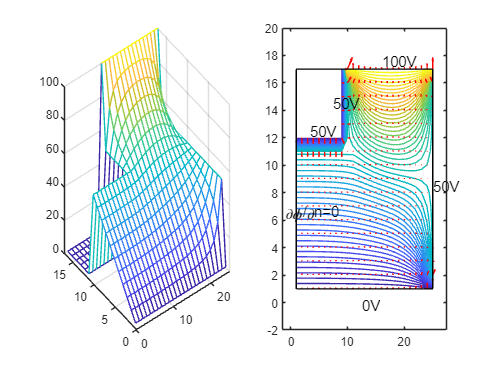

subplot(1,2,1),mesh(v1)                                     % 画三维曲面图
axis([0,25,0,17,0,100])
subplot(1,2,2),contour(v1,50)                               % 画等电位线图

hold on
x=1:1:hx;y=1:1:hy;
[xx,yy]=meshgrid(x,y);                                      % 形成栅格
[Gx,Gy]=gradient(v1,0.6,0.6);                               % 计算梯度
quiver(xx,yy,Gx,Gy,'r')                                     % 根据梯度数据画箭头
axis([-1.5,hx+2.5,-2,20])                                   % 设置坐标边框
plot([1,1,hx,hx,1],[1,hy,hy,1,1],'k')                       % 画导体边框
text(12.5,-0.2,'0V','fontsize',11);   
text(-1.2,6.5,'\partial\phi/\partialn=0','fontsize',11);        
text(25,8.5,'50V','fontsize',11); 
text(3.5,12.5,'50V','fontsize',11);
text(7.5,14.5,'50V','fontsize',11);
text(16,17.6,'100V','fontsize',11);
hold off